participant_dir = "D:\FRM\meta-mutual-learning\data\v2-p-00-3";
kdf_list.machine_ctrl = strcat(participant_dir, "\ml-ctrl-20230209-163730\TrainingData_20230209-163730_163919.kdf");
kdf_list.machine_expl = strcat(participant_dir, "\ml-treat-20230210-170452\TrainingData_20230210-170452_170815.kdf");
kdf_list.mutual_ctrl = strcat(participant_dir, "\cl-ctrl-20230209-164228\TaskData_20230209-164228.kdf");
kdf_list.mutual_expl = strcat(participant_dir, "\cl-treat-20230210-171300\TaskData_20230210-171300.kdf");
kdf_list.human_ctrl = strcat(participant_dir, "\hl-ctrl-20230209-165513\TaskData_20230209-165513.kdf");
kdf_list.human_expl = strcat(participant_dir, "\hl-treat-20230210-173317\TaskData_20230210-173317.kdf");

participant_dir = "D:\FRM\meta-mutual-learning\data\p-03";
kdf_list.machine_ctrl = strcat(participant_dir, "\ml-ctrl-20230223-172533\TrainingData_20230223-172533_172849.kdf");
kdf_list.machine_expl = strcat(participant_dir, "\ml-treat-20230223-164917\TrainingData_20230223-164917_165203.kdf");
kdf_list.mutual_ctrl = strcat(participant_dir, "\cl-ctrl-20230223-173203\TaskData_20230223-173203.kdf");
kdf_list.mutual_expl = strcat(participant_dir, "\cl-treat-20230223-165643\TaskData_20230223-165643.kdf");
kdf_list.human_ctrl = strcat(participant_dir, "\hl-ctrl-20230223-174547\TaskData_20230223-174547.kdf");
kdf_list.human_expl = strcat(participant_dir, "\hl-treat-20230223-171403\TaskData_20230223-171403.kdf");

participant_dir = "D:\FRM\meta-mutual-learning\data\p-04";
kdf_list.machine_ctrl = strcat(participant_dir, "\ml-ctrl-20230303-144441\TrainingData_20230303-144441_144959.kdf");
kdf_list.machine_expl = strcat(participant_dir, "\ml-expl-20230303-153141\TrainingData_20230303-153141_153416.kdf");
kdf_list.mutual_ctrl = strcat(participant_dir, "\cl-ctrl-20230303-145817\TaskData_20230303-145817.kdf");
kdf_list.mutual_expl = strcat(participant_dir, "\cl-ctrl-20230303-145817\TaskData_20230303-145817.kdf");
kdf_list.human_ctrl = strcat(participant_dir, "\hl-ctrl-20230303-151613\TaskData_20230303-151613.kdf");
kdf_list.human_expl = strcat(participant_dir, "\hl-ctrl-20230303-151613\TaskData_20230303-151613.kdf");

p = Participant("Pilot", "Stroke", kdf_list);

Creating new participant: Pilot
	Adding machine learning task
		Adding control experiment
Channel selection
Channel selection
Channel selection
Channel selection
Channel selection
Channel selection
Channel selection
Channel selection
Channel selection
Channel selection
		Adding treatment experiment
Channel selection
Channel selection
Channel selection
Channel selection
Channel selection
Channel selection
Channel selection
Channel selection
Channel selection
Channel selection
	Adding mutual learning task
		Adding control experiment
		Adding treatment experiment
	Adding human learning task
		Adding control experiment
		Adding treatment experiment
Done


## Globals

dof_1_label = "Power Grasp";
dof_1_idx = 5; %% pinky

dof_2_label = "Tripod Grasp";
dof_2_idx = 1; %% thumb

fig_path = "C:\Users\Fredi Mino\Documents\research-projects\meta-mutual-learning\results"; 
fig_type = '.png';
fig_size = [0, 0, 7, 5.25]*2.54; % in to cm
fig_font_size = 13; % 13 px = 10 pt
fig_res = 300; %dpi

## Co-Adaptive Learning Analysis

task_title = "Task 2: Co-Adaptive Learning";

control_tbl = p.mutual_experiment.control_task.data_tbl;
control_t = control_tbl.Time;
control_des = control_tbl.Targets(:,[dof_1_idx, dof_2_idx]);
control_pred = control_tbl.Kalman(:,[dof_1_idx, dof_2_idx]);

experiment_tbl = p.mutual_experiment.experimental_task.data_tbl;
experiment_t = experiment_tbl.Time;
experiment_des = experiment_tbl.Targets(:,[dof_1_idx, dof_2_idx]);
experiment_pred = experiment_tbl.Kalman(:,[dof_1_idx, dof_2_idx]);

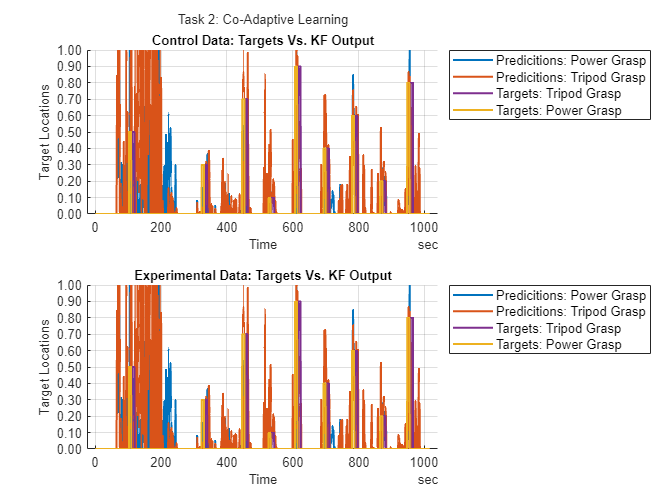

figure('Units','centimeters','Position', fig_size)
tlo = tiledlayout(2,1);
nexttile
plot(control_t, [control_pred, control_des], LineWidth=1.5)
% Change order of lines because 2nd DOF occludes 1st DOF targets
ax = gca;
ax.Children = ax.Children([2 1 3 4]);
legend(strcat("Predicitions: ", dof_1_label), strcat("Predicitions: ", dof_2_label), strcat("Targets: ", dof_2_label), strcat("Targets: ", dof_1_label), Location='northeastoutside')
title('Control Data: Targets Vs. KF Output')
xlabel("Time")
ylabel('Target Locations')
ytickformat('%,0.2f')
yticks([0:0.1:1])
box off
grid on

nexttile
plot(experiment_t, [experiment_pred, experiment_des], LineWidth=1.5)
% Change order of lines because 2nd DOF occludes 1st DOF targets
ax = gca;
ax.Children = ax.Children([2 1 3 4]);
legend(strcat("Predicitions: ", dof_1_label), strcat("Predicitions: ", dof_2_label), strcat("Targets: ", dof_2_label), strcat("Targets: ", dof_1_label), Location='northeastoutside')
title('Experimental Data: Targets Vs. KF Output')
xlabel("Time")
ylabel('Target Locations')
ytickformat('%,0.2f')
yticks([0:0.1:1])
box off
grid on
title(tlo, task_title); 
fontsize(tlo, fig_font_size,"pixels"); exportgraphics(gcf, fullfile(fig_path, strcat("t2-kf-out", fig_type)), "Resolution", fig_res);

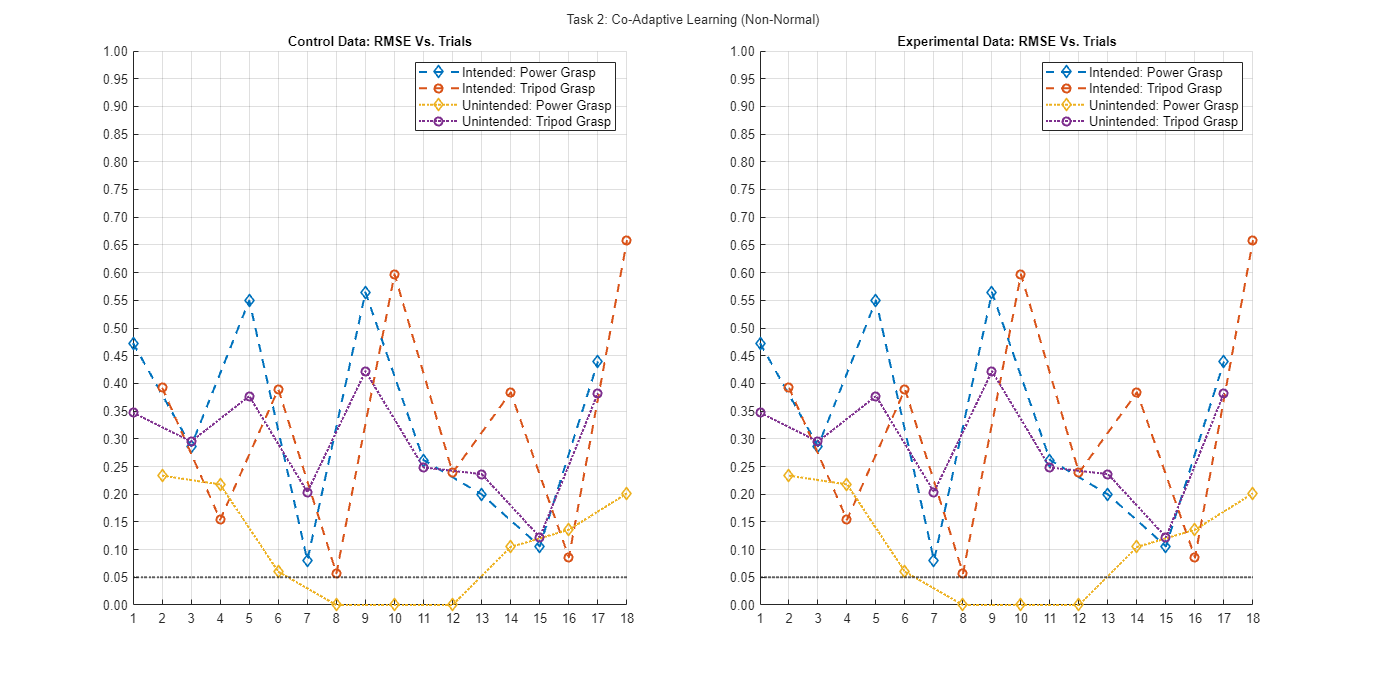

norm_title = "(Non-Normal)";
[control_rmse_int, ~] = my_rmse(control_des, control_pred);
[experiment_rmse_int, ~] = my_rmse(experiment_des, experiment_pred);
figure('Units','centimeters','Position', fig_size)
tlo = plot_rmse_norm(control_rmse_int, experiment_rmse_int, strcat(task_title, " ", norm_title), 1); 
fontsize(tlo, fig_font_size,"pixels"); exportgraphics(gcf, fullfile(fig_path, strcat("t2-rmse-xnorm", fig_type)), "Resolution", fig_res)

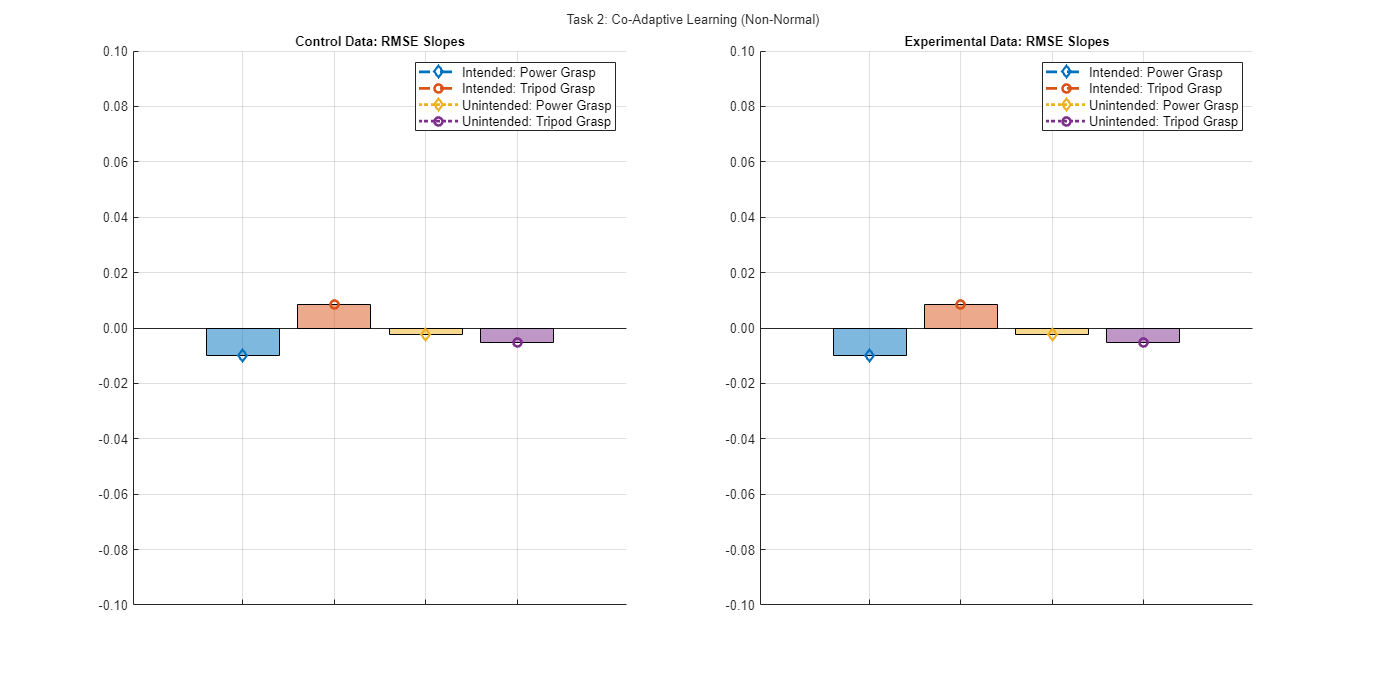

tlo = barplot_rmse_norm(control_rmse_int, experiment_rmse_int, strcat(task_title, " ", norm_title), 1); 
fontsize(tlo, fig_font_size,"pixels"); exportgraphics(gcf, fullfile(fig_path, strcat("t2-bar-xnorm", fig_type)), "Resolution", fig_res)

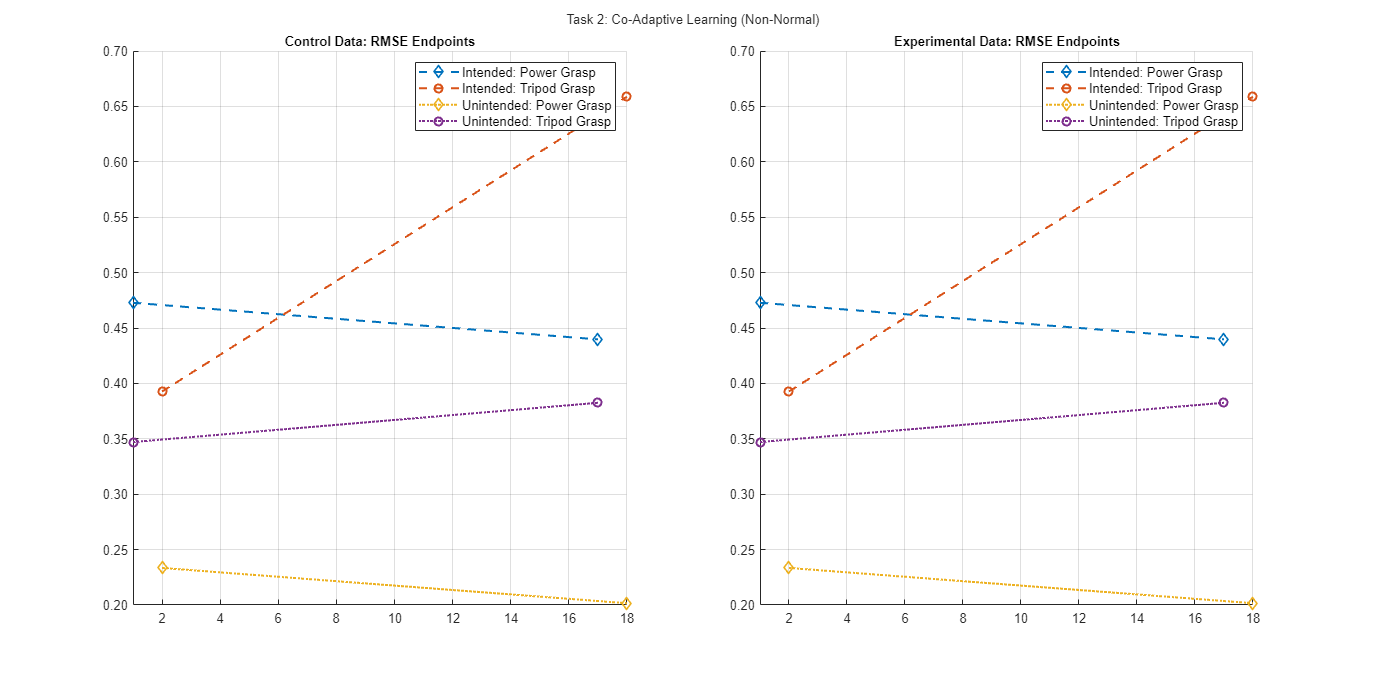

tlo = spaghetti_plot_rmse_norm(control_rmse_int, experiment_rmse_int, strcat(task_title, " ", norm_title), 1); 
fontsize(tlo, fig_font_size,"pixels"); exportgraphics(gcf, fullfile(fig_path, strcat("t2-spaghetti-xnorm", fig_type)), "Resolution", fig_res)

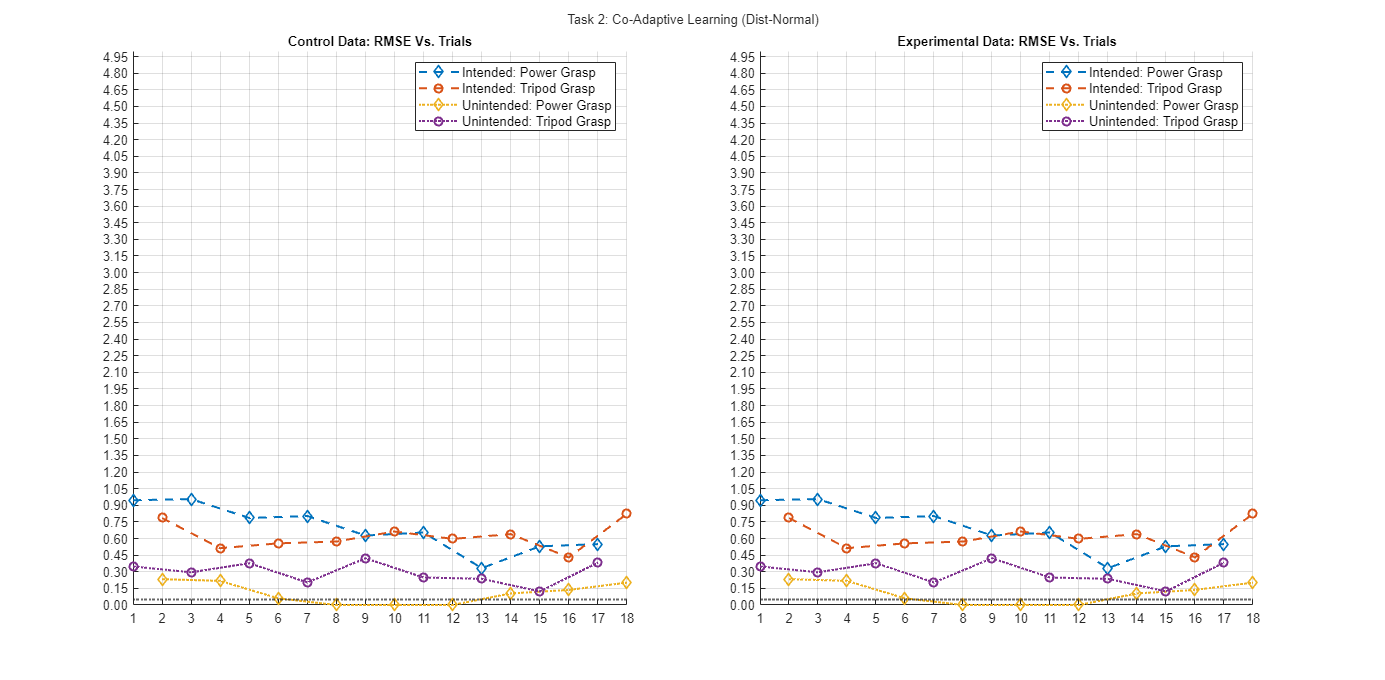

norm_title = "(Dist-Normal)";
norm_dist_lim = 5;
norm_dist_delta = 0.15;
tlo = plot_rmse_norm(control_rmse_int, experiment_rmse_int, strcat(task_title, " ", norm_title), 2);
ax1 = tlo.Children(2);
ax2 = tlo.Children(4);
ylim(ax1, [0, norm_dist_lim])
yticks(ax1, 0:norm_dist_delta:norm_dist_lim)
ylim(ax2, [0, norm_dist_lim])
yticks(ax2, 0:norm_dist_delta:norm_dist_lim);  
fontsize(tlo, fig_font_size,"pixels");exportgraphics(gcf, fullfile(fig_path, strcat("t2-rmse-dnorm", fig_type)), "Resolution", fig_res)

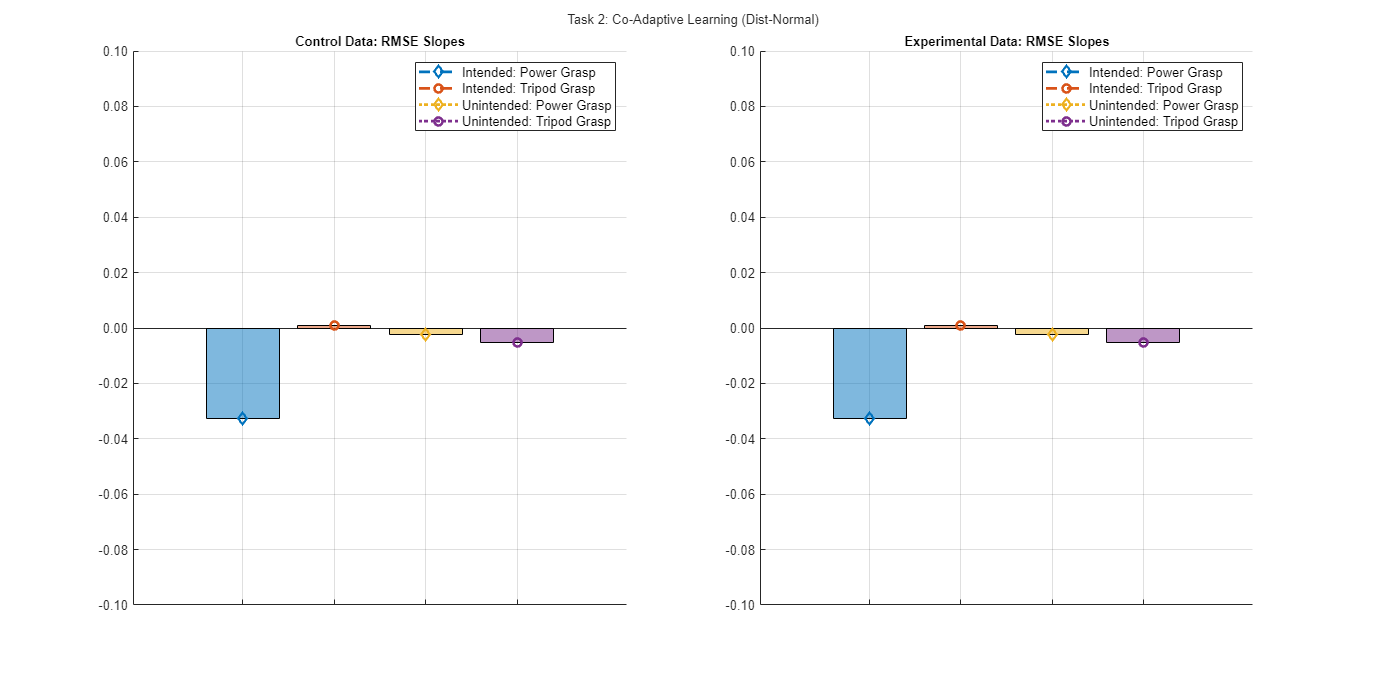

tlo = barplot_rmse_norm(control_rmse_int, experiment_rmse_int, strcat(task_title, " ", norm_title), 2);  
fontsize(tlo, fig_font_size,"pixels");exportgraphics(gcf, fullfile(fig_path, strcat("t2-bar-dnorm", fig_type)), "Resolution", fig_res)

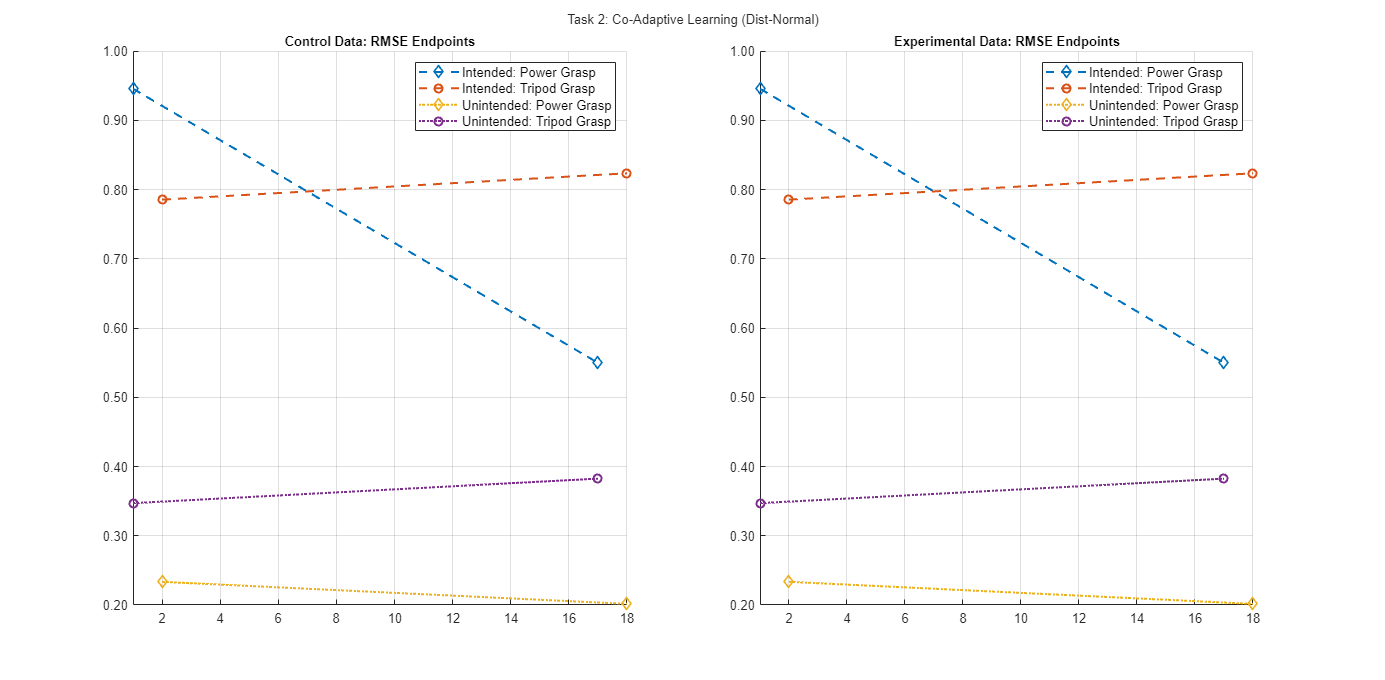

tlo = spaghetti_plot_rmse_norm(control_rmse_int, experiment_rmse_int, strcat(task_title, " ", norm_title), 2);  
fontsize(tlo, fig_font_size,"pixels");exportgraphics(gcf, fullfile(fig_path, strcat("t2-spaghetti-dnorm", fig_type)), "Resolution", fig_res)

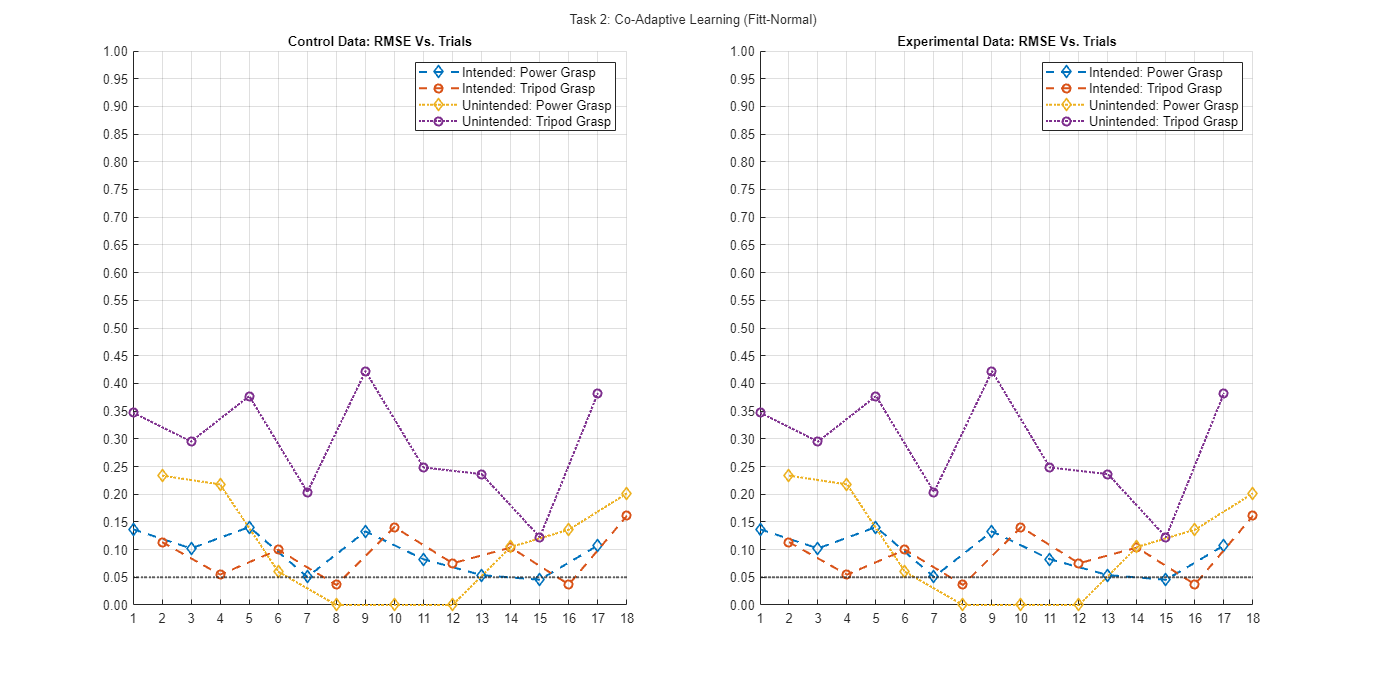

norm_title = "(Fitt-Normal)";
tlo = plot_rmse_norm(control_rmse_int, experiment_rmse_int, strcat(task_title, " ", norm_title), 3);  
fontsize(tlo, fig_font_size,"pixels");exportgraphics(gcf, fullfile(fig_path, strcat("t2-rmse-fnorm", fig_type)), "Resolution", fig_res)

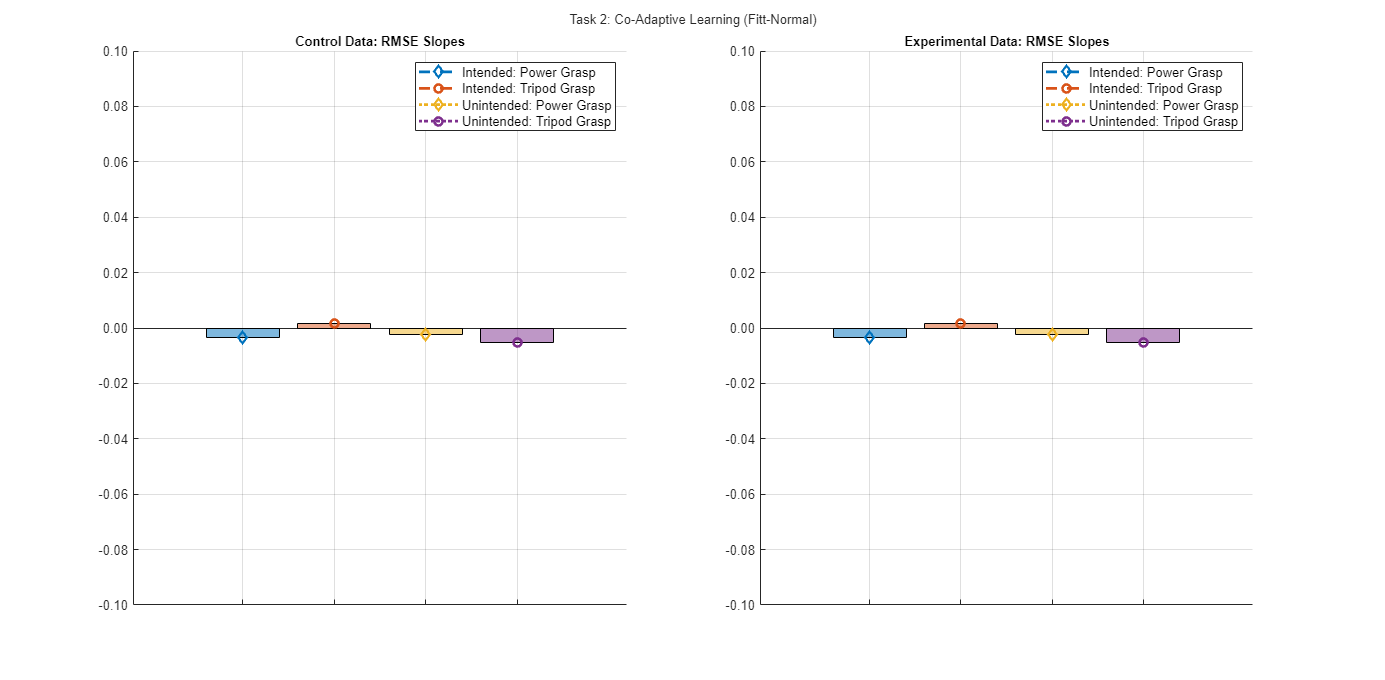

tlo = barplot_rmse_norm(control_rmse_int, experiment_rmse_int, strcat(task_title, " ", norm_title), 3);  
fontsize(tlo, fig_font_size,"pixels");exportgraphics(gcf, fullfile(fig_path, strcat("t2-bar-fnorm", fig_type)), "Resolution", fig_res)

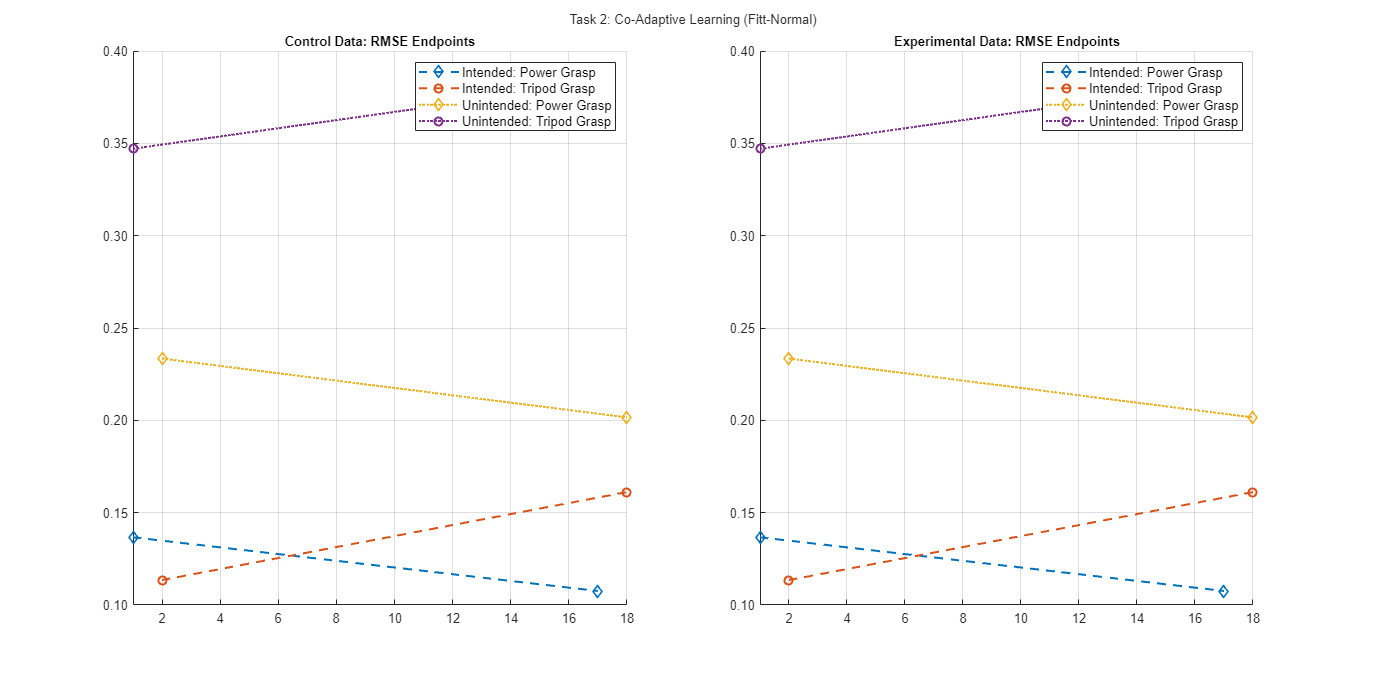

tlo = spaghetti_plot_rmse_norm(control_rmse_int, experiment_rmse_int, strcat(task_title, " ", norm_title), 3);  
fontsize(tlo, fig_font_size,"pixels");exportgraphics(gcf, fullfile(fig_path, strcat("t2-spaghetti-fnorm", fig_type)), "Resolution", fig_res)

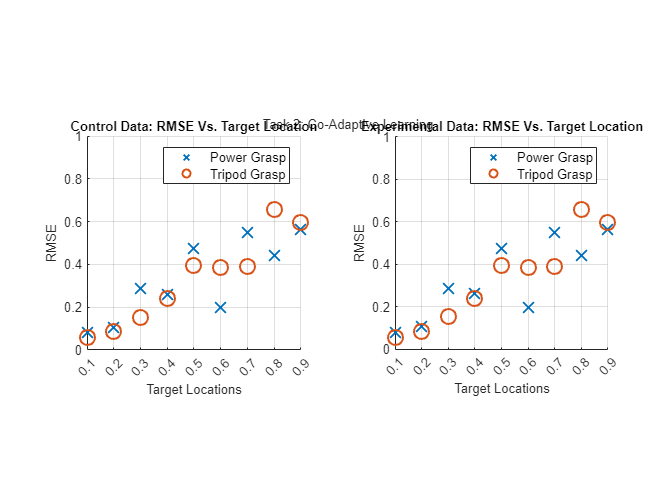

target_vals = repelem([0.5;0.3;0.7;0.1;0.9;0.4;0.6;0.2;0.8], 2);

figure('Units','centimeters','Position',fig_size)
tlo = tiledlayout(1,2);
nexttile
scatter(target_vals(1:2:end), control_rmse_int(1:2:end,1), 125, 'x', LineWidth=1.5)
hold on
scatter(target_vals(2:2:end), control_rmse_int(2:2:end,1), 125, 'o', LineWidth=1.5)
hold off
xlim([0.1, 0.9])
xticks([0.1:0.1:0.9])
xlabel('Target Locations')
ylim([0, 1])
ylabel('RMSE')
grid on
title('Control Data: RMSE Vs. Target Location')
legend(dof_1_label, dof_2_label)
axis square

nexttile
scatter(target_vals(1:2:end), experiment_rmse_int(1:2:end,1), 125, 'x', LineWidth=1.5)
hold on
scatter(target_vals(2:2:end), experiment_rmse_int(2:2:end,1), 125, 'o', LineWidth=1.5)
hold off
xlim([0.1, 0.9])
xticks([0.1:0.1:0.9])
xlabel('Target Locations')
ylim([0, 1])
ylabel('RMSE')
grid on
title('Experimental Data: RMSE Vs. Target Location')
legend(dof_1_label, dof_2_label)
axis square

title(tlo, task_title);  
fontsize(tlo, fig_font_size,"pixels");exportgraphics(gcf, fullfile(fig_path, strcat("t2-rmse-reg", fig_type)), "Resolution", fig_res)

## Human Learning Analysis

task_title = "Task 3: Human Learning";

control_tbl = p.human_experiment.control_task.data_tbl;
control_t = control_tbl.Time;
control_des = control_tbl.Targets(:,[dof_1_idx, dof_2_idx]);
control_pred = control_tbl.Kalman(:,[dof_1_idx, dof_2_idx]);

experiment_tbl = p.human_experiment.experimental_task.data_tbl;
experiment_t = experiment_tbl.Time;
experiment_des = experiment_tbl.Targets(:,[dof_1_idx, dof_2_idx]);
experiment_pred = experiment_tbl.Kalman(:,[dof_1_idx, dof_2_idx]);

### Data Viz

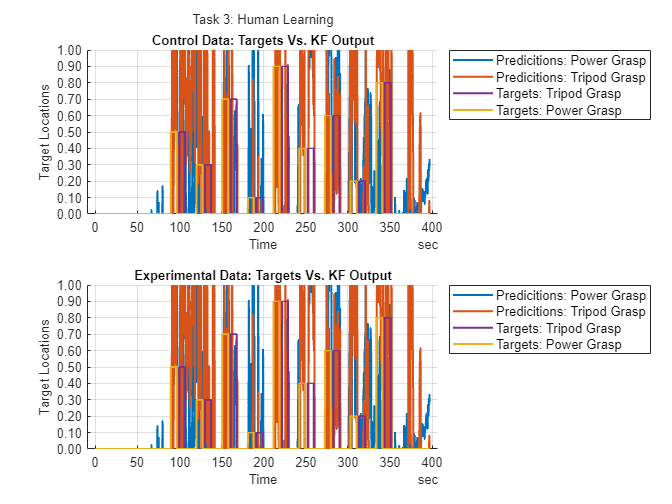

figure('Units','centimeters','Position',fig_size)
tlo = tiledlayout(2,1);
nexttile
plot(control_t, [control_pred, control_des], LineWidth=1.5)
% Change order of lines because 2nd DOF occludes 1st DOF targets
ax = gca;
ax.Children = ax.Children([2 1 3 4]);
legend(strcat("Predicitions: ", dof_1_label), strcat("Predicitions: ", dof_2_label), strcat("Targets: ", dof_2_label), strcat("Targets: ", dof_1_label), Location='northeastoutside')
title('Control Data: Targets Vs. KF Output')
xlabel("Time")
ylabel('Target Locations')
ytickformat('%,0.2f')
yticks([0:0.1:1])
box off
grid on

nexttile
plot(experiment_t, [experiment_pred, experiment_des], LineWidth=1.5)
% Change order of lines because 2nd DOF occludes 1st DOF targets
ax = gca;
ax.Children = ax.Children([2 1 3 4]);
legend(strcat("Predicitions: ", dof_1_label), strcat("Predicitions: ", dof_2_label), strcat("Targets: ", dof_2_label), strcat("Targets: ", dof_1_label), Location='northeastoutside')
title('Experimental Data: Targets Vs. KF Output')
xlabel("Time")
ylabel('Target Locations')
ytickformat('%,0.2f')
yticks([0:0.1:1])
box off
grid on
title(tlo, task_title); 
fontsize(tlo, fig_font_size,"pixels"); exportgraphics(gcf, fullfile(fig_path, strcat("t3-kf-out", fig_type)), "Resolution", fig_res)

### RMSE

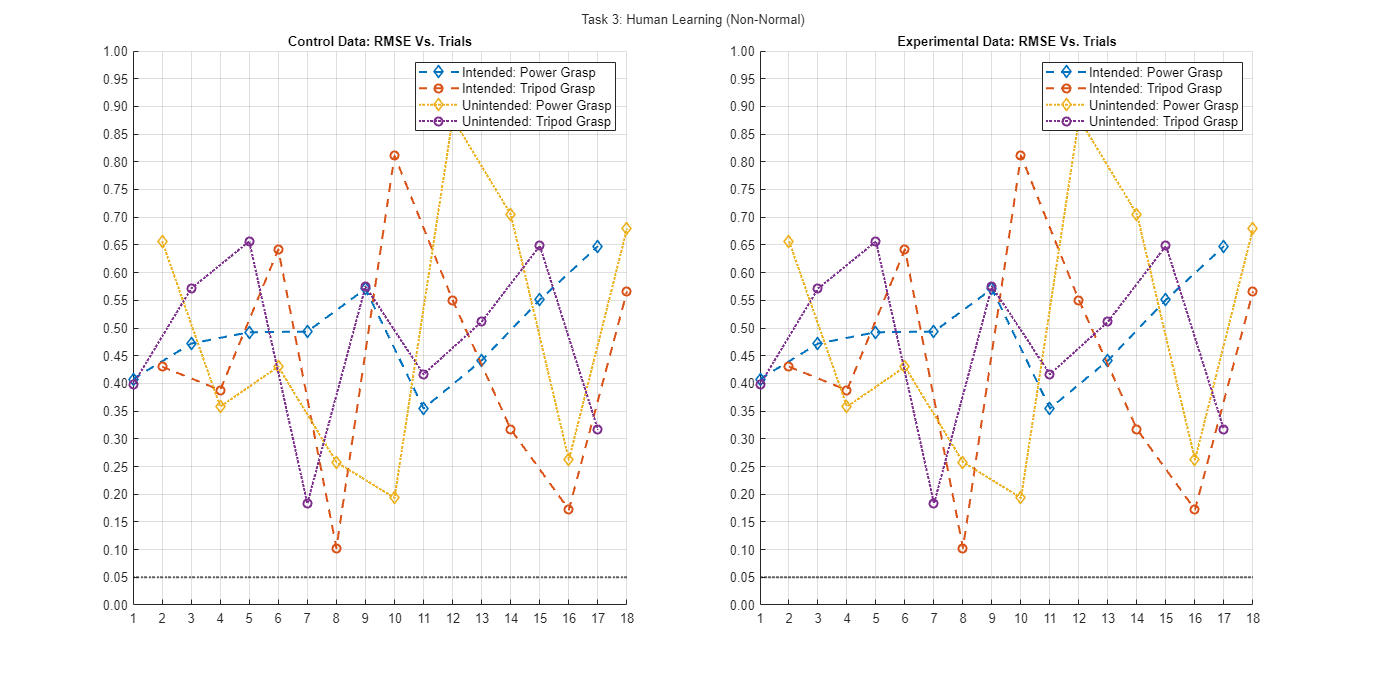

[control_rmse_int, ~] = my_rmse(control_des, control_pred);
[experiment_rmse_int, ~] = my_rmse(experiment_des, experiment_pred);

norm_title = "(Non-Normal)";
figure('Units','centimeters','Position',fig_size)
% For P03: control_rmse_int = [ NaN,NaN; NaN,NaN; control_rmse_int]
tlo = plot_rmse_norm(control_rmse_int, experiment_rmse_int, strcat(task_title, " ", norm_title), 1); 
fontsize(tlo, fig_font_size,"pixels"); exportgraphics(gcf, fullfile(fig_path, strcat("t3-rmse-xnorm", fig_type)), "Resolution", fig_res)

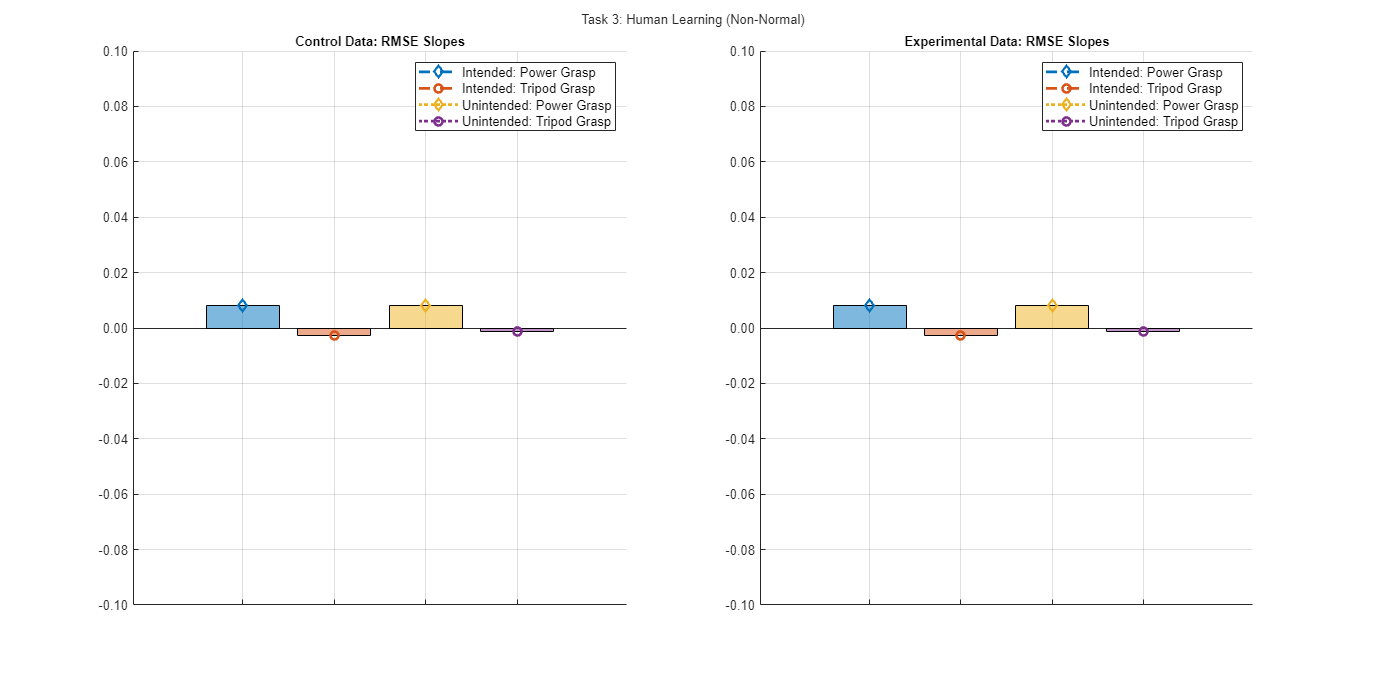

tlo = barplot_rmse_norm(control_rmse_int, experiment_rmse_int, strcat(task_title, " ", norm_title), 1); 
fontsize(tlo, fig_font_size,"pixels"); exportgraphics(gcf, fullfile(fig_path, strcat("t3-bar-xnorm", fig_type)), "Resolution", fig_res)

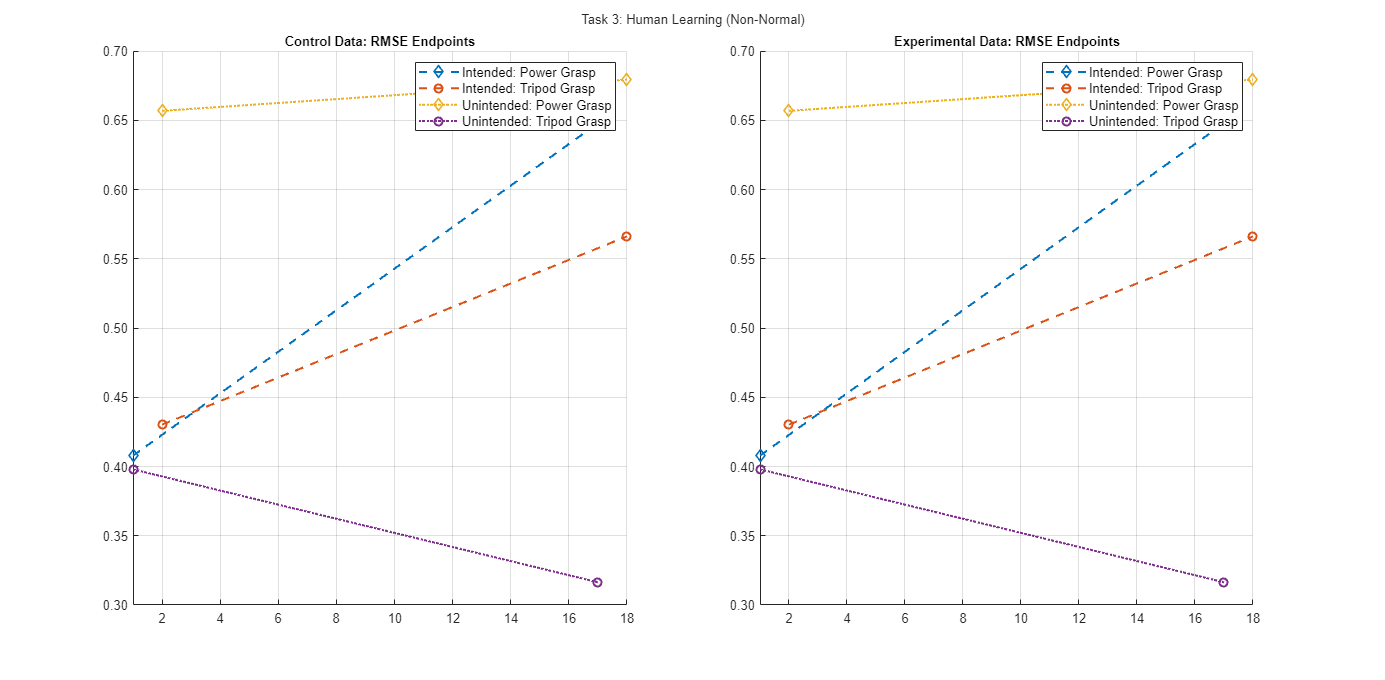

tlo = spaghetti_plot_rmse_norm(control_rmse_int, experiment_rmse_int, strcat(task_title, " ", norm_title), 1); 
fontsize(tlo, fig_font_size,"pixels"); exportgraphics(gcf, fullfile(fig_path, strcat("t3-spaghetti-xnorm", fig_type)), "Resolution", fig_res)

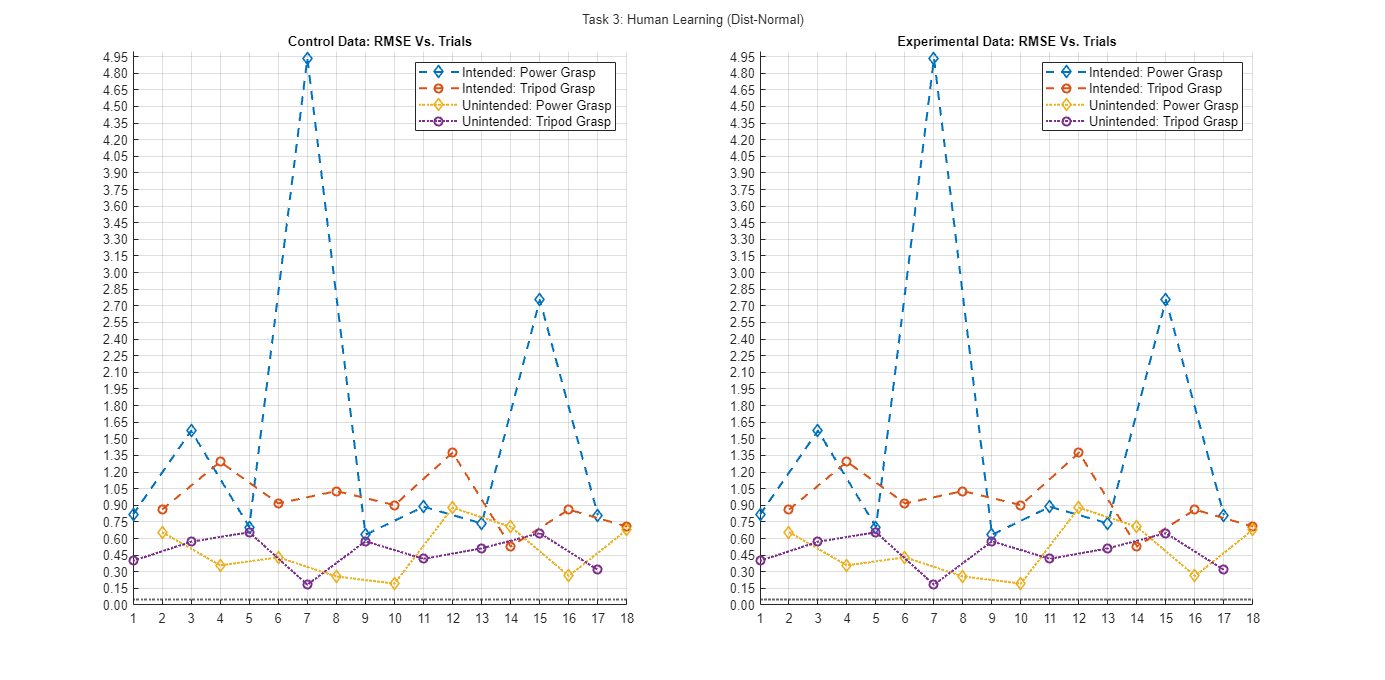

norm_title = "(Dist-Normal)";
tlo = plot_rmse_norm(control_rmse_int, experiment_rmse_int, strcat(task_title, " ", norm_title), 2);
ax1 = tlo.Children(2);
ax2 = tlo.Children(4);
ylim(ax1, [0, norm_dist_lim])
yticks(ax1, 0:norm_dist_delta:norm_dist_lim)
ylim(ax2, [0, norm_dist_lim])
yticks(ax2, 0:norm_dist_delta:norm_dist_lim); 
fontsize(tlo, fig_font_size,"pixels"); exportgraphics(gcf, fullfile(fig_path, strcat("t3-rmse-dnorm", fig_type)), "Resolution", fig_res)

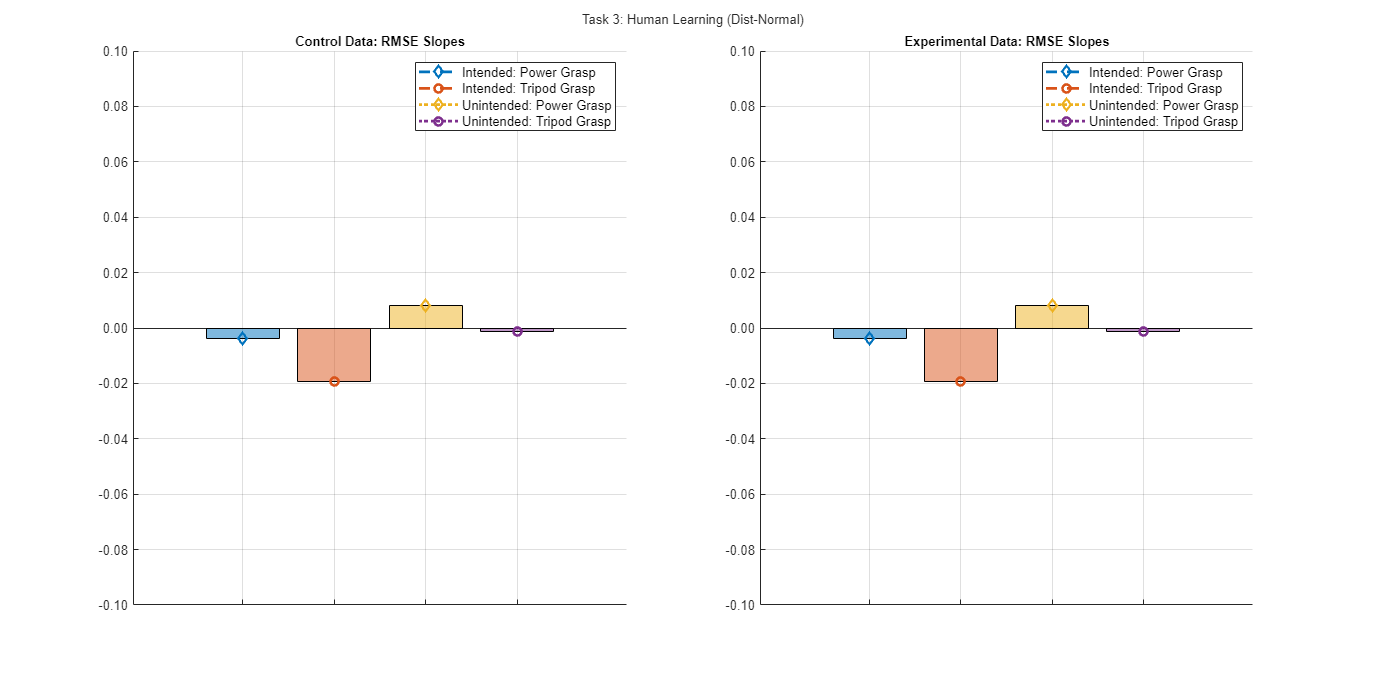

tlo = barplot_rmse_norm(control_rmse_int, experiment_rmse_int, strcat(task_title, " ", norm_title), 2); 
fontsize(tlo, fig_font_size,"pixels"); exportgraphics(gcf, fullfile(fig_path, strcat("t3-bar-dnorm", fig_type)), "Resolution", fig_res)

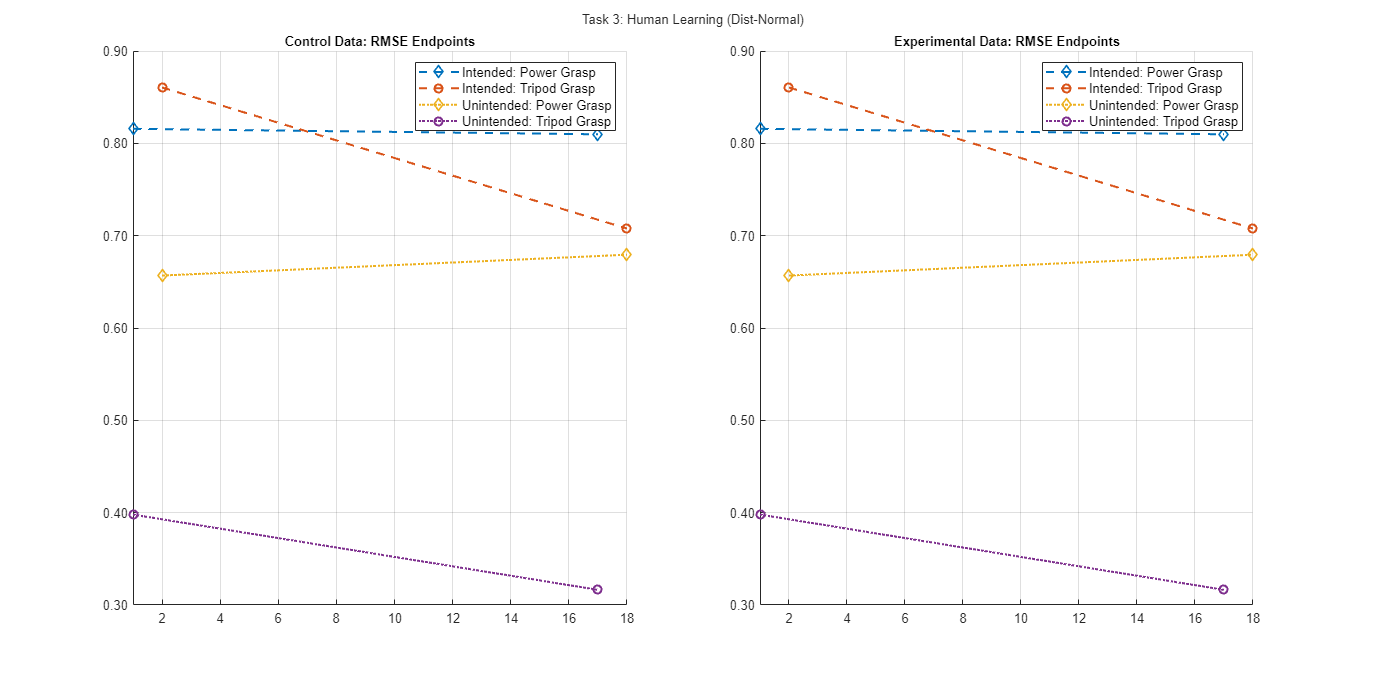

tlo = spaghetti_plot_rmse_norm(control_rmse_int, experiment_rmse_int, strcat(task_title, " ", norm_title), 2); 
fontsize(tlo, fig_font_size,"pixels"); exportgraphics(gcf, fullfile(fig_path, strcat("t3-spaghetti-dnorm", fig_type)), "Resolution", fig_res)

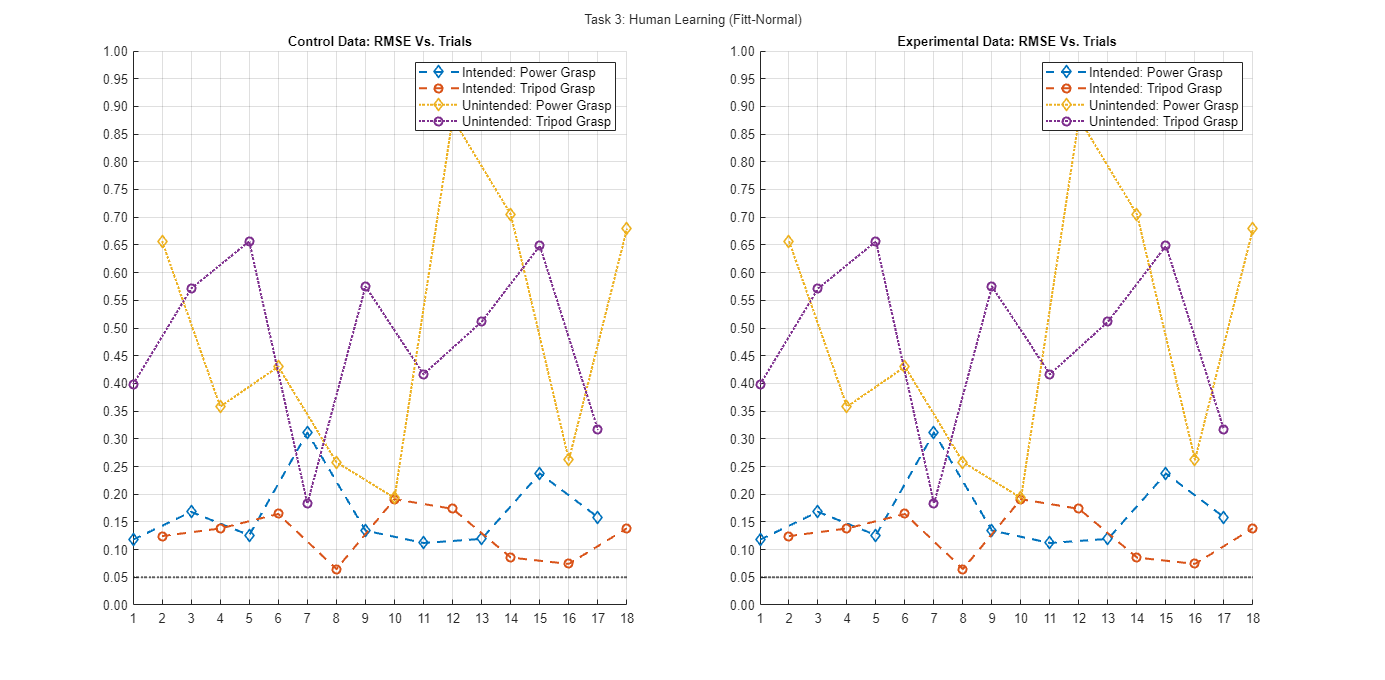

norm_title = "(Fitt-Normal)";
tlo = plot_rmse_norm(control_rmse_int, experiment_rmse_int, strcat(task_title, " ", norm_title), 3); 
fontsize(tlo, fig_font_size,"pixels"); exportgraphics(gcf, fullfile(fig_path, strcat("t3-rmse-fnorm", fig_type)), "Resolution", fig_res)

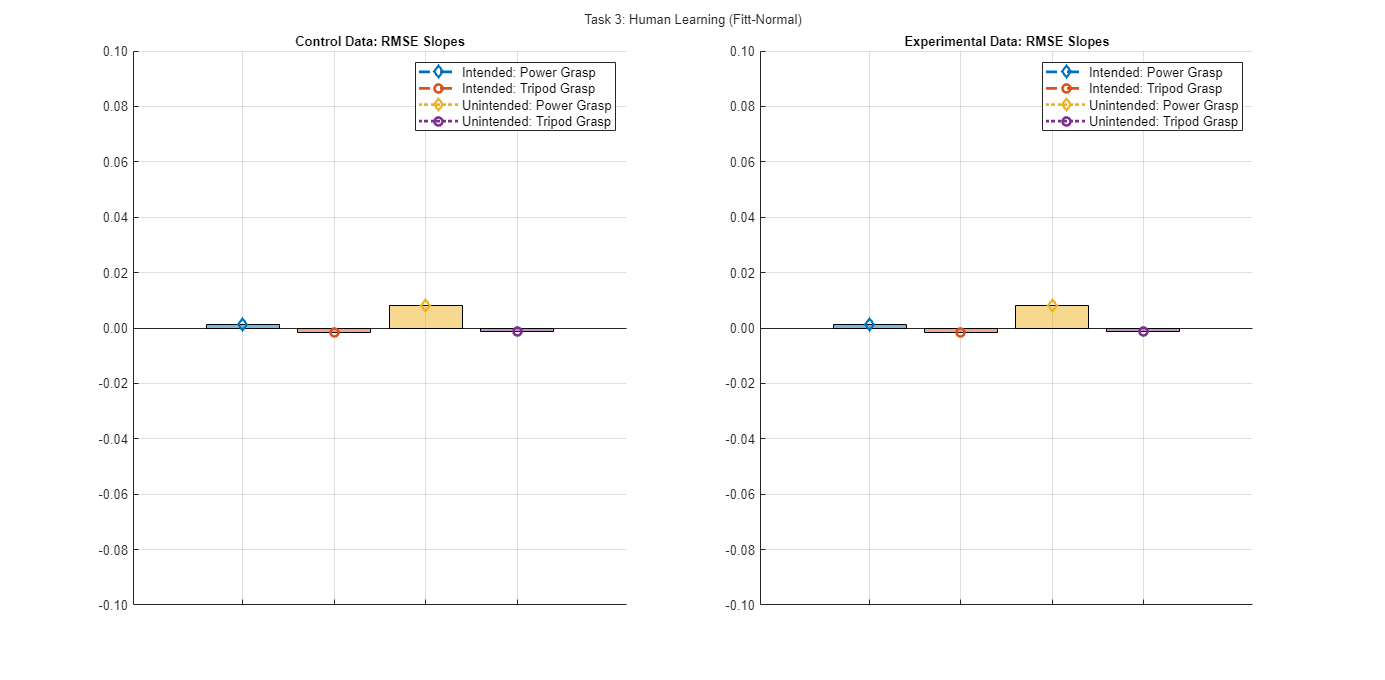

tlo = barplot_rmse_norm(control_rmse_int, experiment_rmse_int, strcat(task_title, " ", norm_title), 3); 
fontsize(tlo, fig_font_size,"pixels"); exportgraphics(gcf, fullfile(fig_path, strcat("t3-bar-fnorm", fig_type)), "Resolution", fig_res)

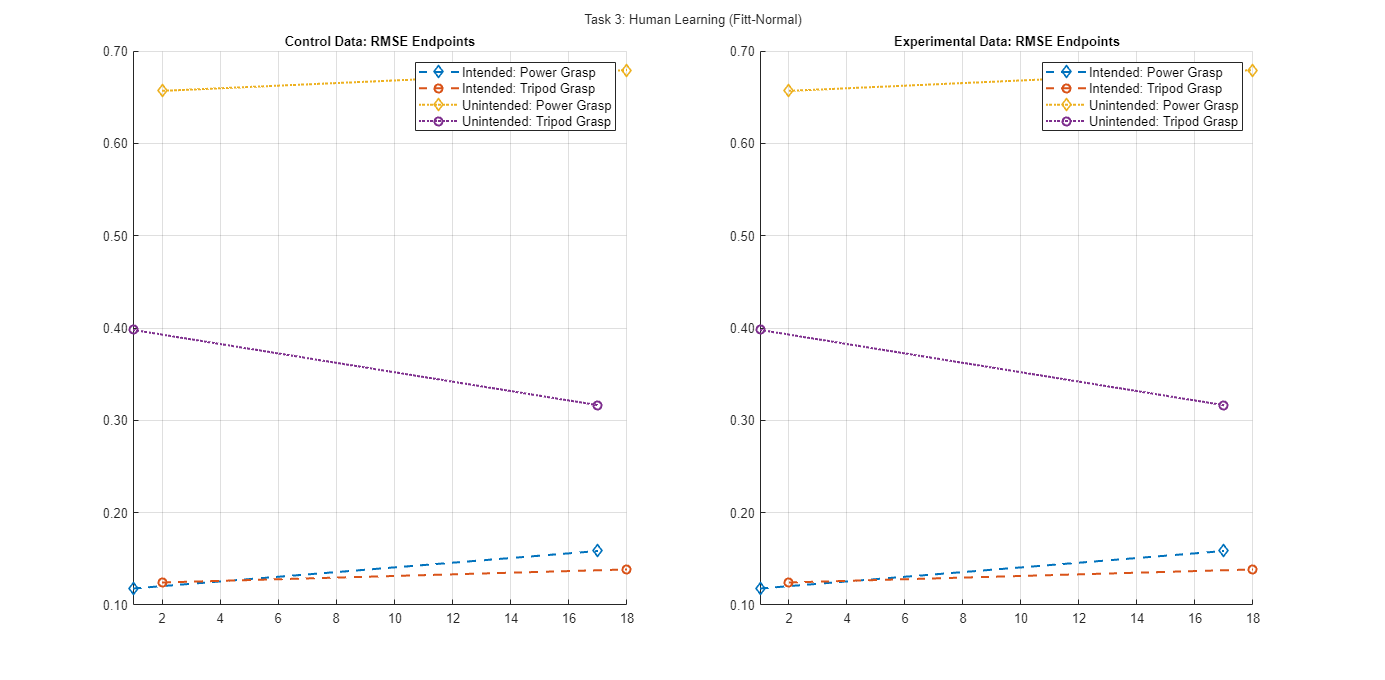

tlo = spaghetti_plot_rmse_norm(control_rmse_int, experiment_rmse_int, strcat(task_title, " ", norm_title), 3); 
fontsize(tlo, fig_font_size,"pixels"); exportgraphics(gcf, fullfile(fig_path, strcat("t3-spaghetti-fnorm", fig_type)), "Resolution", fig_res)

### RMSE Distribution

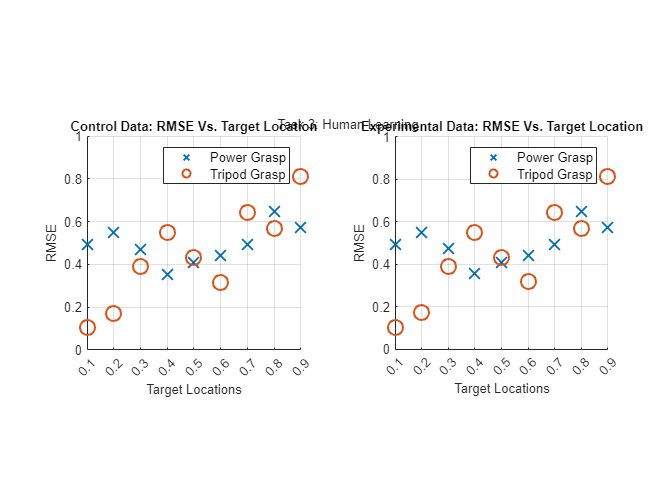

figure('Units','centimeters','Position',fig_size)
tlo = tiledlayout(1,2);
nexttile
% P03: scatter(target_vals(1:2:end), [NaN; control_rmse_int(1:2:end,1)], 125, 'x', LineWidth=1.5)
scatter(target_vals(1:2:end), control_rmse_int(1:2:end,1), 125, 'x', LineWidth=1.5)
hold on
% P03: scatter(target_vals(2:2:end), [NaN; control_rmse_int(2:2:end,1)], 125, 'o', LineWidth=1.5)
scatter(target_vals(2:2:end), control_rmse_int(2:2:end,1), 125, 'o', LineWidth=1.5)
hold off
xlim([0.1, 0.9])
xticks([0.1:0.1:0.9])
xlabel('Target Locations')
ylim([0, 1])
ylabel('RMSE')
grid on
title('Control Data: RMSE Vs. Target Location')
legend(dof_1_label, dof_2_label)
axis square

nexttile
scatter(target_vals(1:2:end), experiment_rmse_int(1:2:end,1), 125, 'x', LineWidth=1.5)
hold on
scatter(target_vals(2:2:end), experiment_rmse_int(2:2:end,1), 125, 'o', LineWidth=1.5)
hold off
xlim([0.1, 0.9])
xticks([0.1:0.1:0.9])
xlabel('Target Locations')
ylim([0, 1])
ylabel('RMSE')
grid on
title('Experimental Data: RMSE Vs. Target Location')
legend(dof_1_label, dof_2_label)
axis square

title(tlo, task_title); 
fontsize(tlo, fig_font_size,"pixels"); exportgraphics(gcf, fullfile(fig_path, strcat("t3-rmse-reg", fig_type)), "Resolution", fig_res)

## Machine Learning Analysis

task_title = "Task 1: Machine Learning";

control_tbl = p.machine_experiment.control_task.data_tbl;
control_t = control_tbl.Time;
control_des = control_tbl.Targets(:,[dof_1_idx, dof_2_idx]);

experiment_tbl = p.machine_experiment.experimental_task.data_tbl;
experiment_t = experiment_tbl.Time;
experiment_des = experiment_tbl.Targets(:,[dof_1_idx, dof_2_idx]);
experiment_pred = experiment_tbl.Kalman_02(:,[dof_1_idx, dof_2_idx]);

% start on 4th column: [NIP, Targets, Features, Kalman1, Kalman2, ..., Kinematics]
kf_idxs = 4:width(control_tbl)-1;

for i = 1:length(kf_idxs)
kf_pred = control_tbl(:, kf_idxs(i)).Variables;
control_pred = kf_pred(:, [dof_1_idx, dof_2_idx]);
[control_rmse_int, ~] = my_rmse(control_des, control_pred);
if i ==1
    knit_rmse = control_rmse_int(2*i+1:2*i+2,:);
elseif i < length(kf_idxs)
    knit_rmse = [knit_rmse; control_rmse_int(2*i+1:2*i+2,:)];
end
% disp(num_filters(i))
end
control_rmse_knit = knit_rmse;

kf_idxs = 4:width(experiment_tbl)-1;

for i = 1:length(kf_idxs)
kf_pred = experiment_tbl(:,kf_idxs(i)).Variables;
experiment_pred = kf_pred(:,[dof_1_idx, dof_2_idx]);
[experiment_rmse_int, ~] = my_rmse([0, 0; experiment_des], [0,0;experiment_pred]);
if i ==1
    knit_rmse = experiment_rmse_int(2*i+1:2*i+2,:);
elseif i < length(kf_idxs)
    knit_rmse = [knit_rmse; experiment_rmse_int(2*i+1:2*i+2,:)];
end
% disp(num_filters(i))
end
experiment_rmse_knit = knit_rmse;

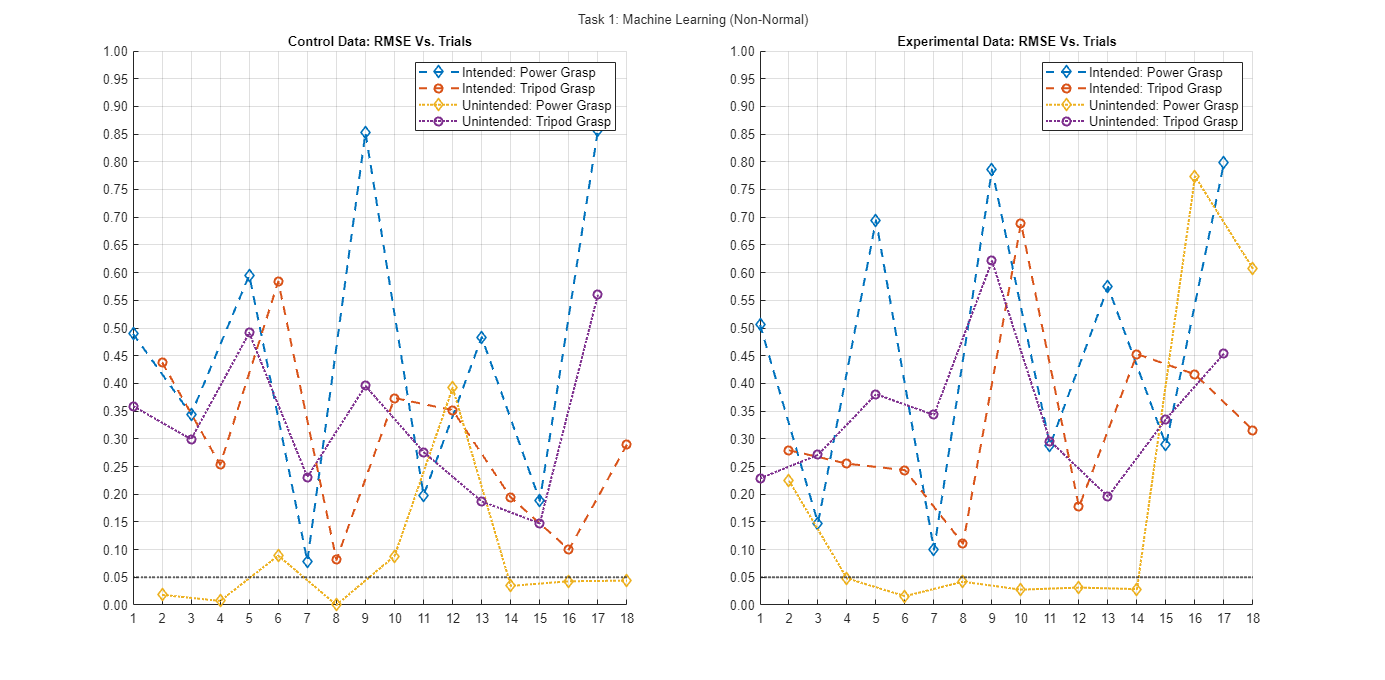

norm_title = "(Non-Normal)";
figure('Units','centimeters','Position',fig_size)
tlo = plot_rmse_norm(control_rmse_knit, experiment_rmse_knit, strcat(task_title, " ", norm_title), 1); 
fontsize(tlo, fig_font_size,"pixels"); exportgraphics(gcf, fullfile(fig_path, strcat("t1-rmse-xnorm", fig_type)), "Resolution", fig_res)

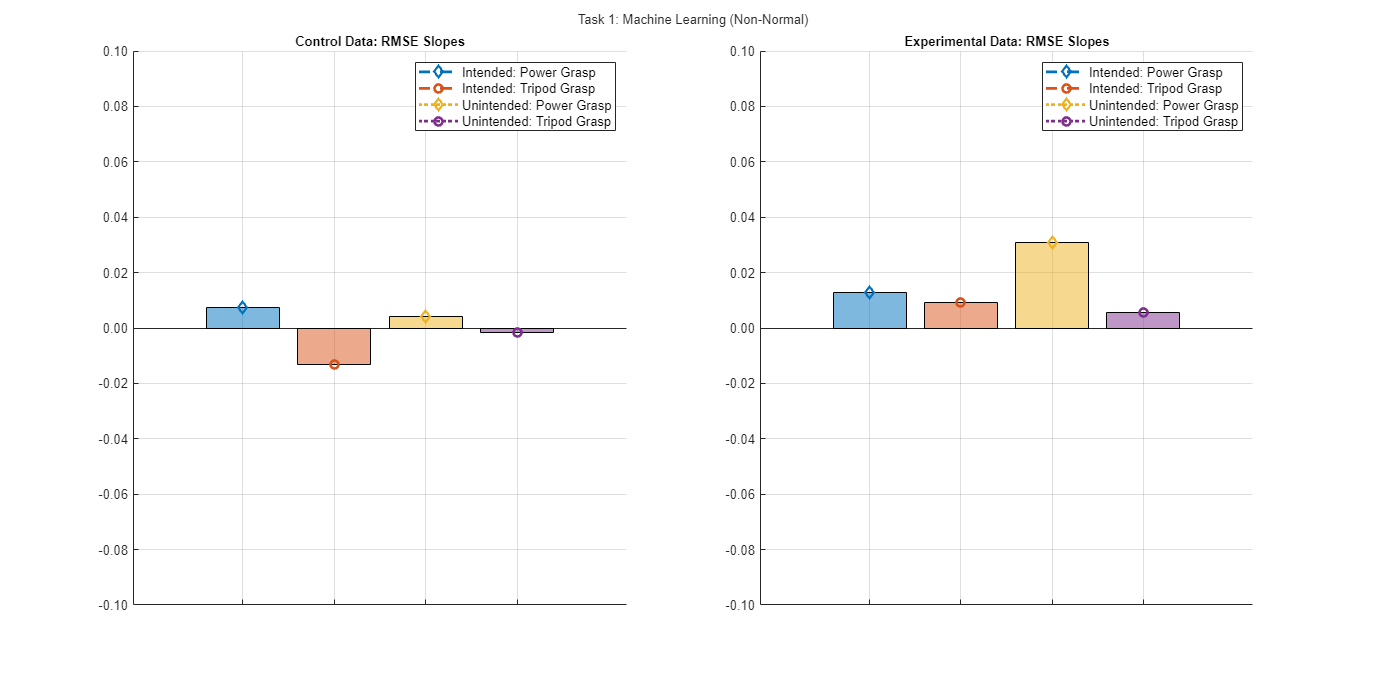

tlo = barplot_rmse_norm(control_rmse_knit, experiment_rmse_knit, strcat(task_title, " ", norm_title), 1); 
fontsize(tlo, fig_font_size,"pixels"); exportgraphics(gcf, fullfile(fig_path, strcat("t1-bar-xnorm", fig_type)), "Resolution", fig_res)

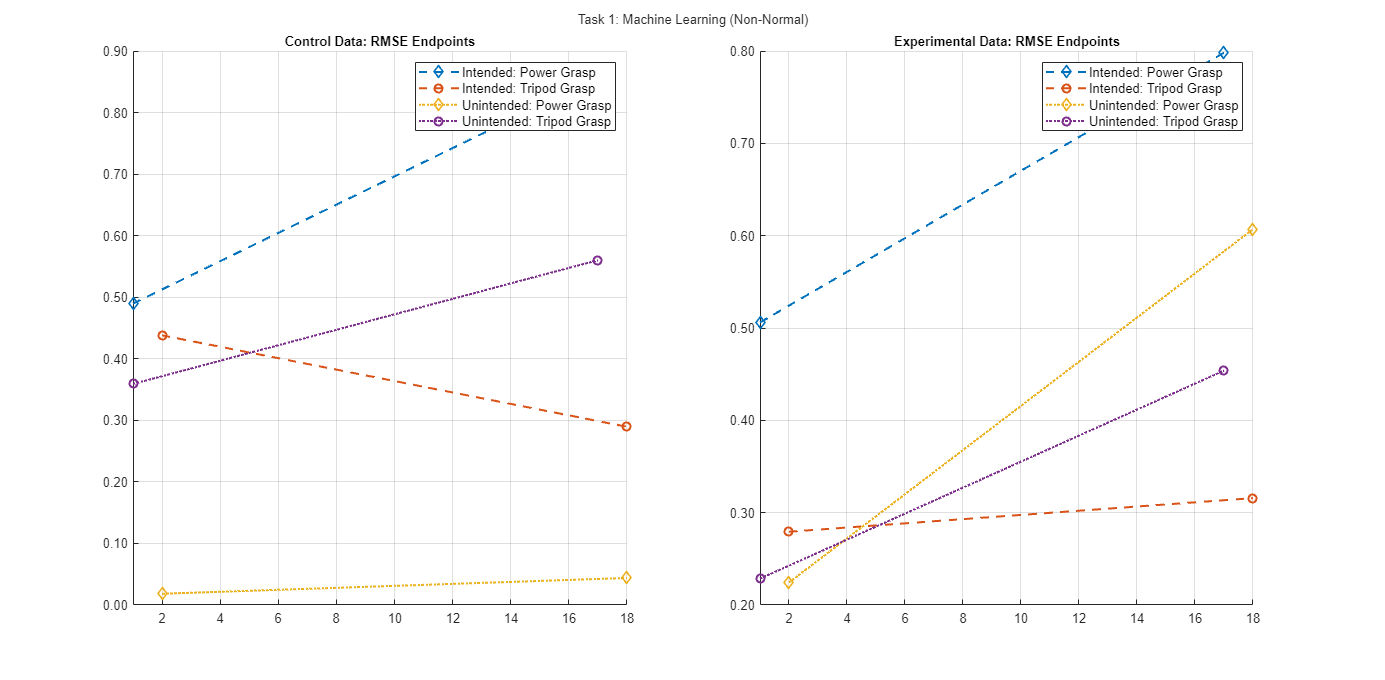

tlo = spaghetti_plot_rmse_norm(control_rmse_knit, experiment_rmse_knit, strcat(task_title, " ", norm_title), 1); 
fontsize(tlo, fig_font_size,"pixels"); exportgraphics(gcf, fullfile(fig_path, strcat("t1-spaghetti-xnorm", fig_type)), "Resolution", fig_res)

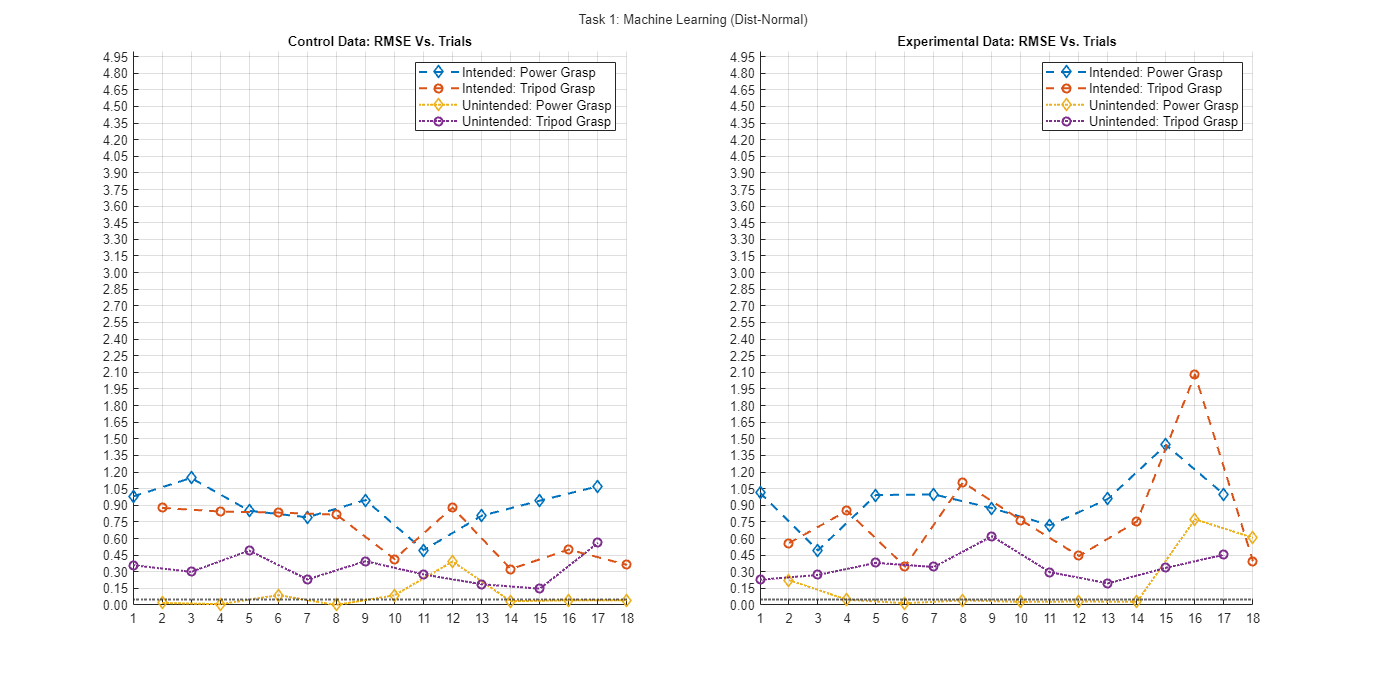

norm_title = "(Dist-Normal)";
tlo = plot_rmse_norm(control_rmse_knit, experiment_rmse_knit, strcat(task_title, " ", norm_title), 2);
ax1 = tlo.Children(2);
ax2 = tlo.Children(4);
ylim(ax1, [0, norm_dist_lim])
yticks(ax1, 0:norm_dist_delta:norm_dist_lim)
ylim(ax2, [0, norm_dist_lim])
yticks(ax2, 0:norm_dist_delta:norm_dist_lim); 
fontsize(tlo, fig_font_size,"pixels"); exportgraphics(gcf, fullfile(fig_path, strcat("t1-rmse-dnorm", fig_type)), "Resolution", fig_res)

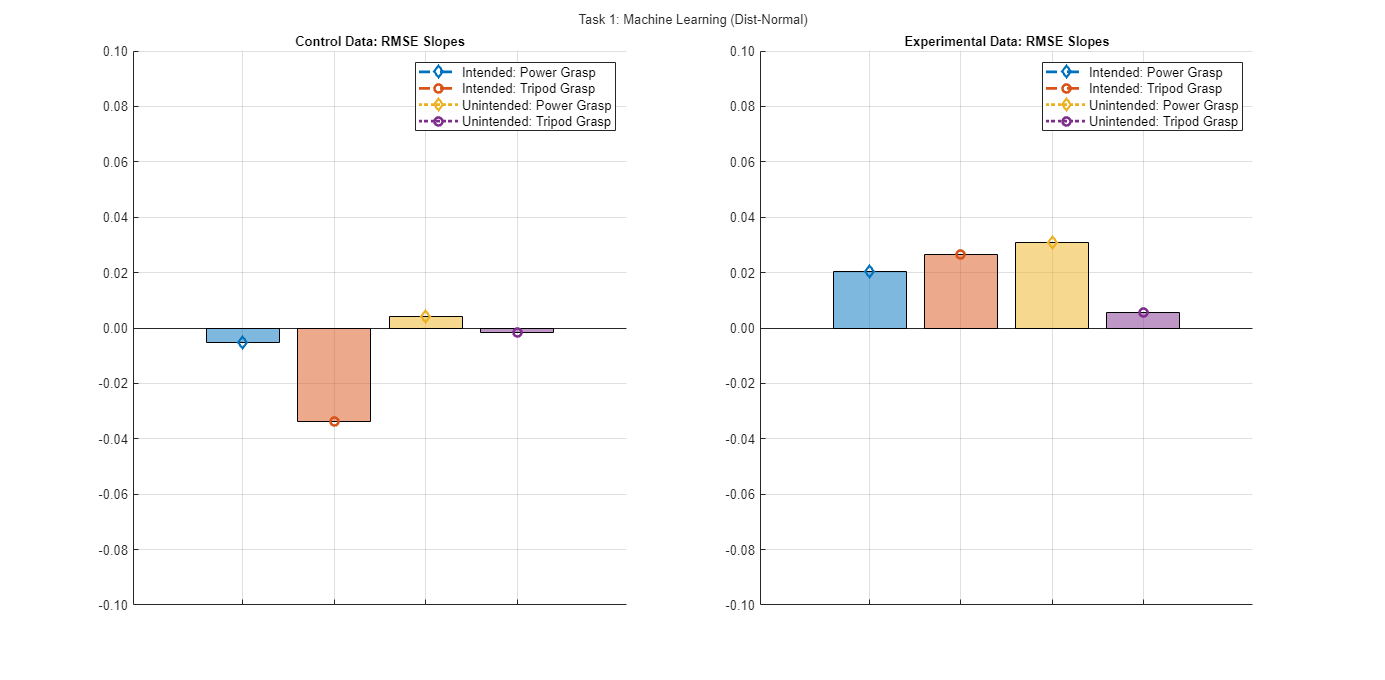

tlo = barplot_rmse_norm(control_rmse_knit, experiment_rmse_knit, strcat(task_title, " ", norm_title), 2); 
fontsize(tlo, fig_font_size,"pixels"); exportgraphics(gcf, fullfile(fig_path, strcat("t1-bar-dnorm", fig_type)), "Resolution", fig_res)

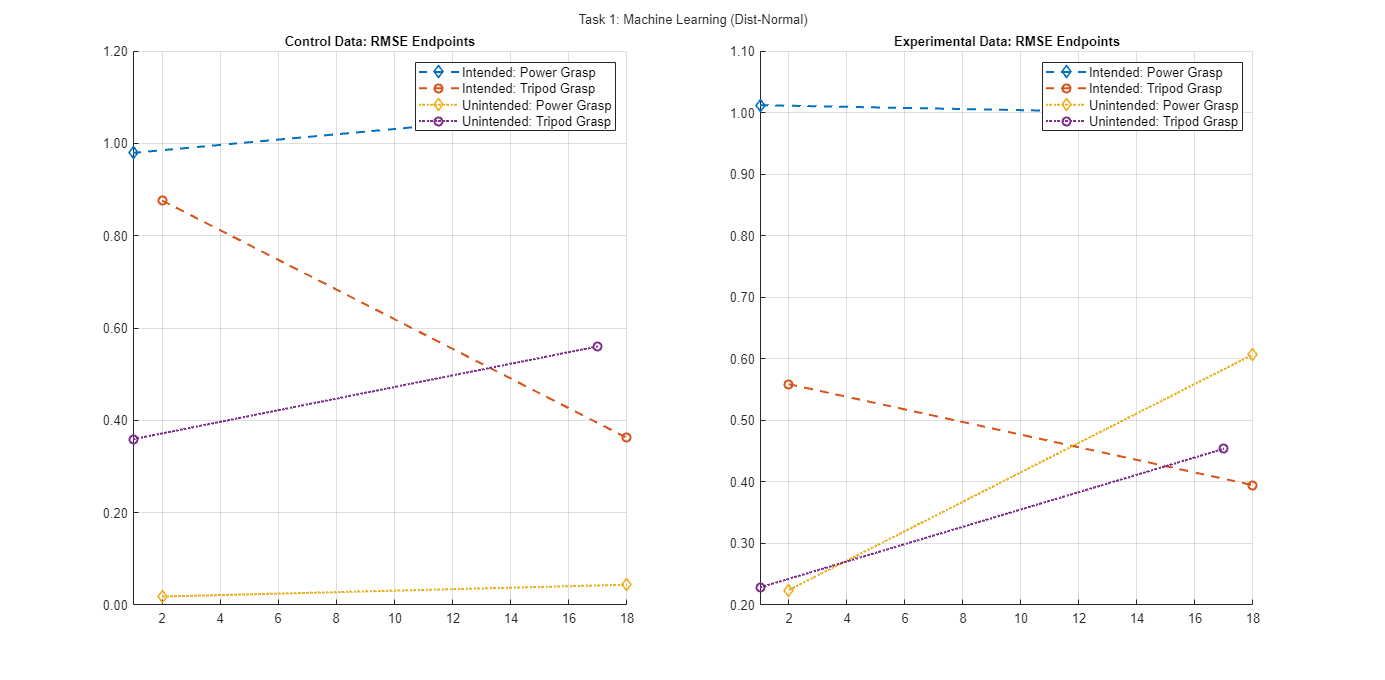

tlo = spaghetti_plot_rmse_norm(control_rmse_knit, experiment_rmse_knit, strcat(task_title, " ", norm_title), 2); 
fontsize(tlo, fig_font_size,"pixels"); exportgraphics(gcf, fullfile(fig_path, strcat("t1-spaghetti-dnorm", fig_type)), "Resolution", fig_res)

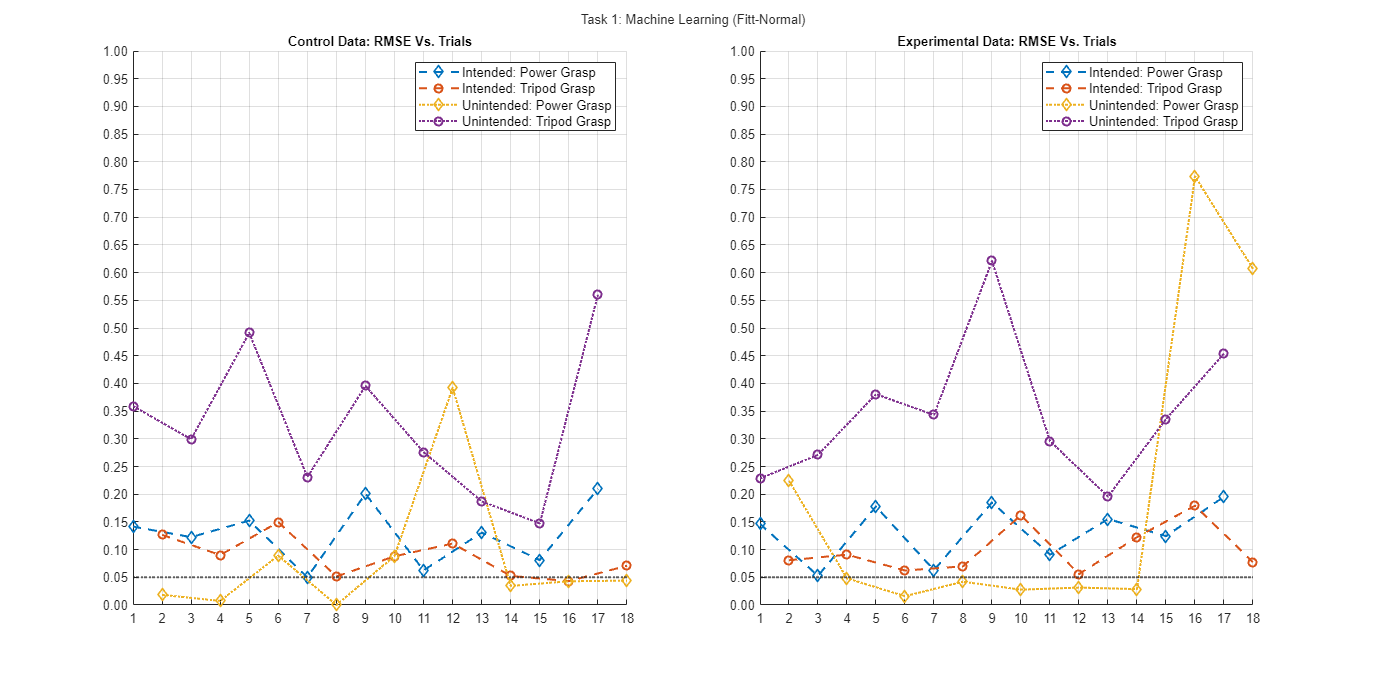

norm_title = "(Fitt-Normal)";
tlo = plot_rmse_norm(control_rmse_knit, experiment_rmse_knit, strcat(task_title, " ", norm_title), 3); 
fontsize(tlo, fig_font_size,"pixels"); exportgraphics(gcf, fullfile(fig_path, strcat("t1-rmse-fnorm", fig_type)), "Resolution", fig_res)

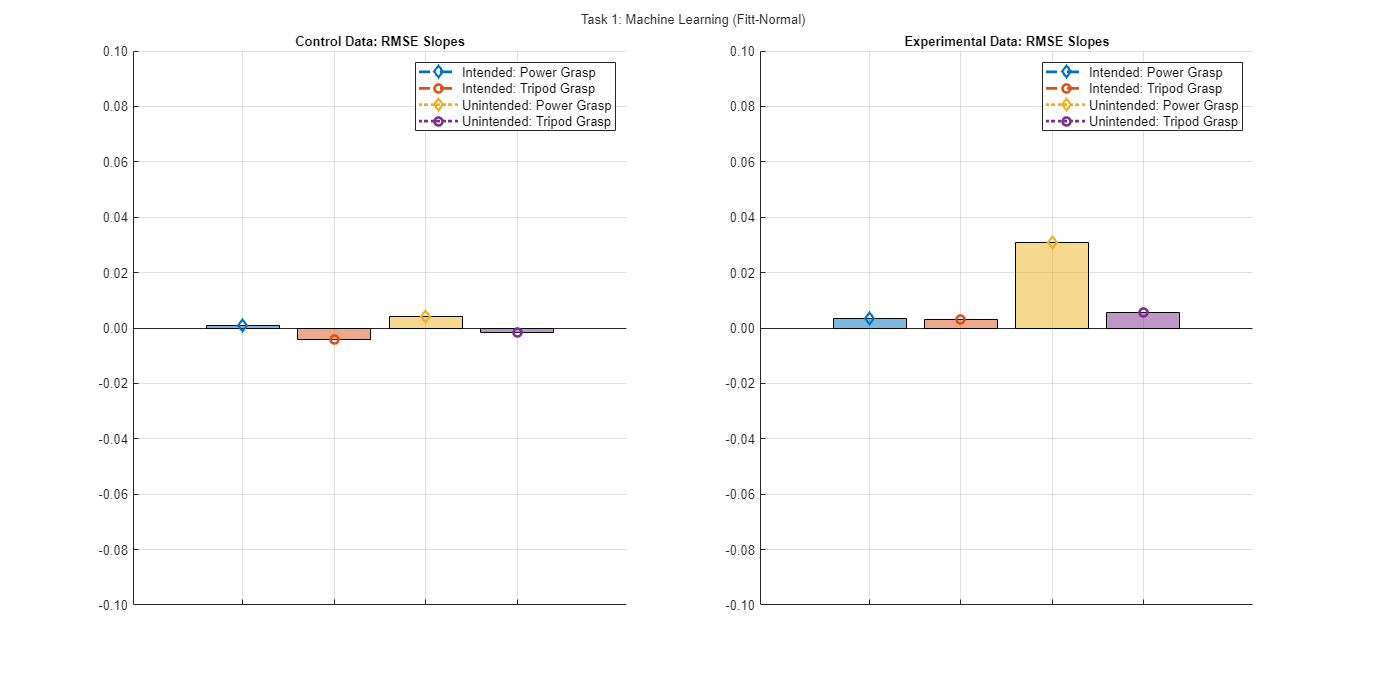

tlo = barplot_rmse_norm(control_rmse_knit, experiment_rmse_knit, strcat(task_title, " ", norm_title), 3); 
fontsize(tlo, fig_font_size,"pixels"); exportgraphics(gcf, fullfile(fig_path, strcat("t1-bar-fnorm", fig_type)), "Resolution", fig_res)

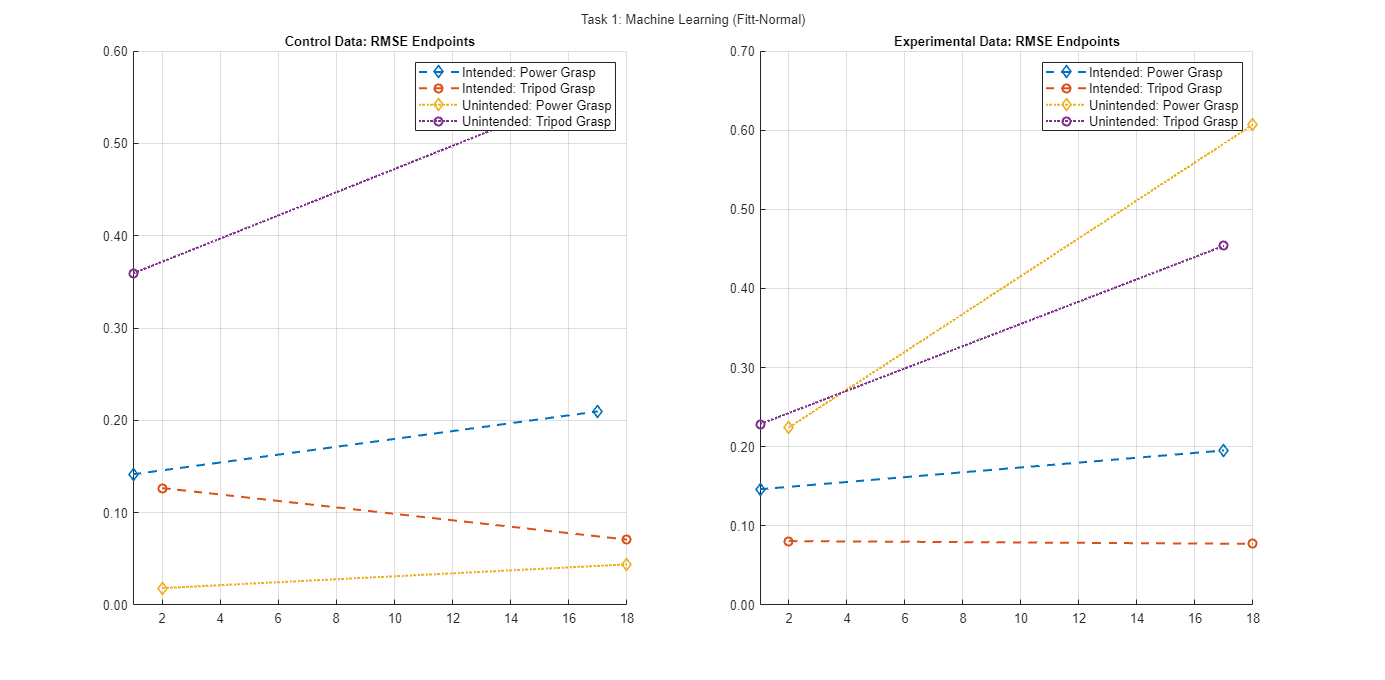

tlo = spaghetti_plot_rmse_norm(control_rmse_knit, experiment_rmse_knit, strcat(task_title, " ", norm_title), 3); 
fontsize(tlo, fig_font_size,"pixels"); exportgraphics(gcf, fullfile(fig_path, strcat("t1-spaghetti-fnorm", fig_type)), "Resolution", fig_res)

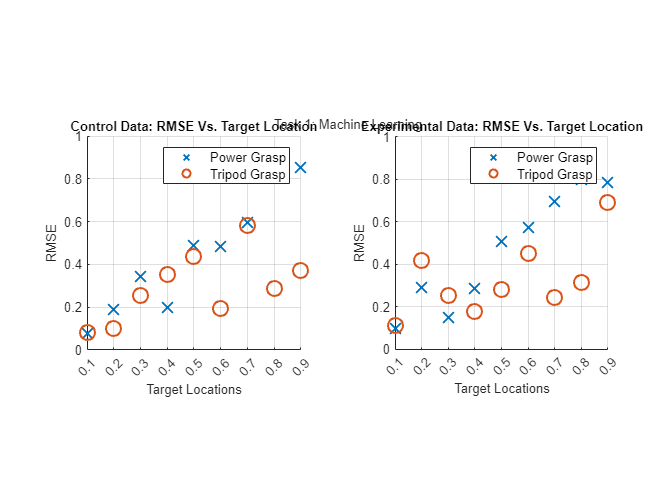

figure('Units','centimeters','Position',fig_size)
tlo = tiledlayout(1,2);
nexttile
scatter(target_vals(1:2:end), control_rmse_knit(1:2:end,1), 125, 'x', LineWidth=1.5)
hold on
scatter(target_vals(2:2:end), control_rmse_knit(2:2:end,1), 125, 'o', LineWidth=1.5)
hold off
xlim([0.1, 0.9])
xticks([0.1:0.1:0.9])
xlabel('Target Locations')
ylim([0, 1])
ylabel('RMSE')
grid on
title('Control Data: RMSE Vs. Target Location')
legend(dof_1_label, dof_2_label)
axis square

nexttile
scatter(target_vals(1:2:end), experiment_rmse_knit(1:2:end,1), 125, 'x', LineWidth=1.5)
hold on
scatter(target_vals(2:2:end), experiment_rmse_knit(2:2:end,1), 125, 'o', LineWidth=1.5)
hold off
xlim([0.1, 0.9])
xticks([0.1:0.1:0.9])
xlabel('Target Locations')
ylim([0, 1])
ylabel('RMSE')
grid on
title('Experimental Data: RMSE Vs. Target Location')
legend(dof_1_label, dof_2_label)
axis square

title(tlo, task_title); 
fontsize(tlo, fig_font_size,"pixels"); exportgraphics(gcf, fullfile(fig_path, strcat("t1-rmse-reg", fig_type)), "Resolution", fig_res)

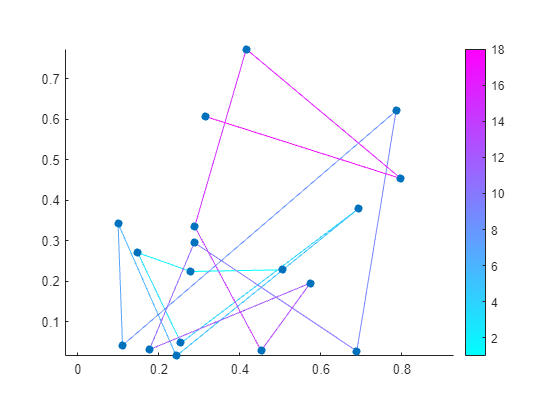

% figure
% plot(RMSE, 'o:')
% xticks([1:20])
% yticks([0:0.05:1])
% ylim([0 1])
% ytickformat('%,0.2f')
% grid on
% box off
% title('RMSE Over Time')
% legend(["Grasp","Pronation"])

figure
% color_vec = 1:length(RMSE_ordered);
% scatter(RMSE_ordered(:,1), RMSE_ordered(:,2), [], color_vec, 'o', 'filled');
% colormap(jet)
% hold on
% plot(RMSE_ordered(:,1), RMSE_ordered(:,2),':')
% hold off
x=experiment_rmse_knit(:,1);
y=experiment_rmse_knit(:,2);
c=1:numel(x);
colormap(cool); % or whatever colormap you want
surface('XData',  [x(:) x(:)],'YData',[y(:) y(:)],...
        'ZData',0*[x(:) x(:)],'CData',[c(:) c(:)],'EdgeColor','flat');
hold on
scatter(x,y,'o', 'filled')
hold off
axis equal
colorbar

function [rmse_by_int, rmse_by_class] = my_rmse(desired, predicted)
square_error = (desired - predicted).^2;
trial_starts = find(diff(any(desired, 2)) > 0);
trial_stops = find(diff(any(desired, 2)) < 0);
RMSE = -1*ones(length(trial_starts),2);
for i=1:1:length(trial_starts)
    SE_window = square_error(trial_starts(i):trial_stops(i),:);
    RMSE(i,:) = sqrt(sum(SE_window)./length(SE_window));
end

RMSE_ordered = RMSE;
for i=2:2:length(RMSE)
    RMSE_ordered(i,[1 2]) = RMSE_ordered(i,[2 1]);
end
rmse_by_int = RMSE_ordered;
rmse_by_class = RMSE;
end
% trial_stops = find(diff(any(desired, 2)) < 0);
function [RMSE] = my_model_rmse(desired, predicted, stop_idx)
square_error = (desired - predicted).^2;
SE_window = square_error(1:stop_idx,:);
RMSE(1,:) = sqrt(sum(SE_window)./length(SE_window));
end